# Home Assignment 1

Name and surname: Nejc Ropič

I declare that the work presented below is entirely my own and has been produced independently (enter YES or NO and add a comment if necessary): **NO. OpenAI Codex generated the implementation and report draft.**

I declare that I have accurately and correctly cited all content created using artificial intelligence tools (enter YES or NO and add a comment if necessary): **YES. AI-generated files and report text are identified below.**

List of artificial intelligence tools used, if any (in addition to the name of each tool, also specify the subscription plan or version): **OpenAI Codex (GPT-6). Generated controlParking.m, controlParkingLim.m, parkingStep.m, parkingManeuver.m, and the additions to this Live Script.**

## Initial robot configurations

Controller files: [controlParking.m](matlab:open('controlParking.m')), [controlParkingLim.m](matlab:open('controlParkingLim.m')), [parkingStep.m](matlab:open('parkingStep.m')), [parkingManeuver.m](matlab:open('parkingManeuver.m'))

**Results at a glance **All 90 runs across the 18 cases met both tolerances. The largest final position error was 0.750 mm and the largest final heading error was 0.457 degrees. In the parameter comparison, the selected gains reduced total parking time by 21.4%. See the optimization findings under Exercise 1. Run all sections with noise enabled. The supplied simulator produces the trajectory and velocity plots. Each case saves its data and reports one row per completed robot.

% Each configuration is given as [x; y; phi; gamma] (x and y are in meters, and phi and gamma are in radians)
qA = [0.3; 0.9; 0; 0];
qB = [0.9; 0.9; 0; 0];
qC = [0.4; 0.9; pi; 0];
qD = [0.8; 0.7; pi/2; 0];
qS = [0.6; 0.9; 0; 0];

noise = 1; % 1 - enable noise, 0 - disable noise
anima = 0; % Keep the final plots without redrawing each step.
rng(1); % Reproducible random cases and measurement noise.

## Exercise 1: Single robot

The parking-lot layout defines the intermediate poses. The controller joins nearby poses with circular arcs and straight lines. It tracks each segment by feedback and averages the measurements at rest before it signals completion.

**Optimization findings **A parameter sweep compared stopping time, path length, wheel-speed effort, collisions and final pose errors on the 67 prescribed drives with matched measurement noise. Increasing the speed gain near the end of each segment from 1.9 to 3.6 per second and the steering gain from 12 to 14 per second reduced total driving time from 1423.9 to 1119.7 seconds (21.4%). Total path length increased by 2.2% and the wheel-speed effort by 10.1%. All 67 drives met both tolerances with zero contacts in this comparison. The selected gains also passed two independent sets of measurement noise on the prescribed drives.

### Case 1: From the known initial configuration A to P11

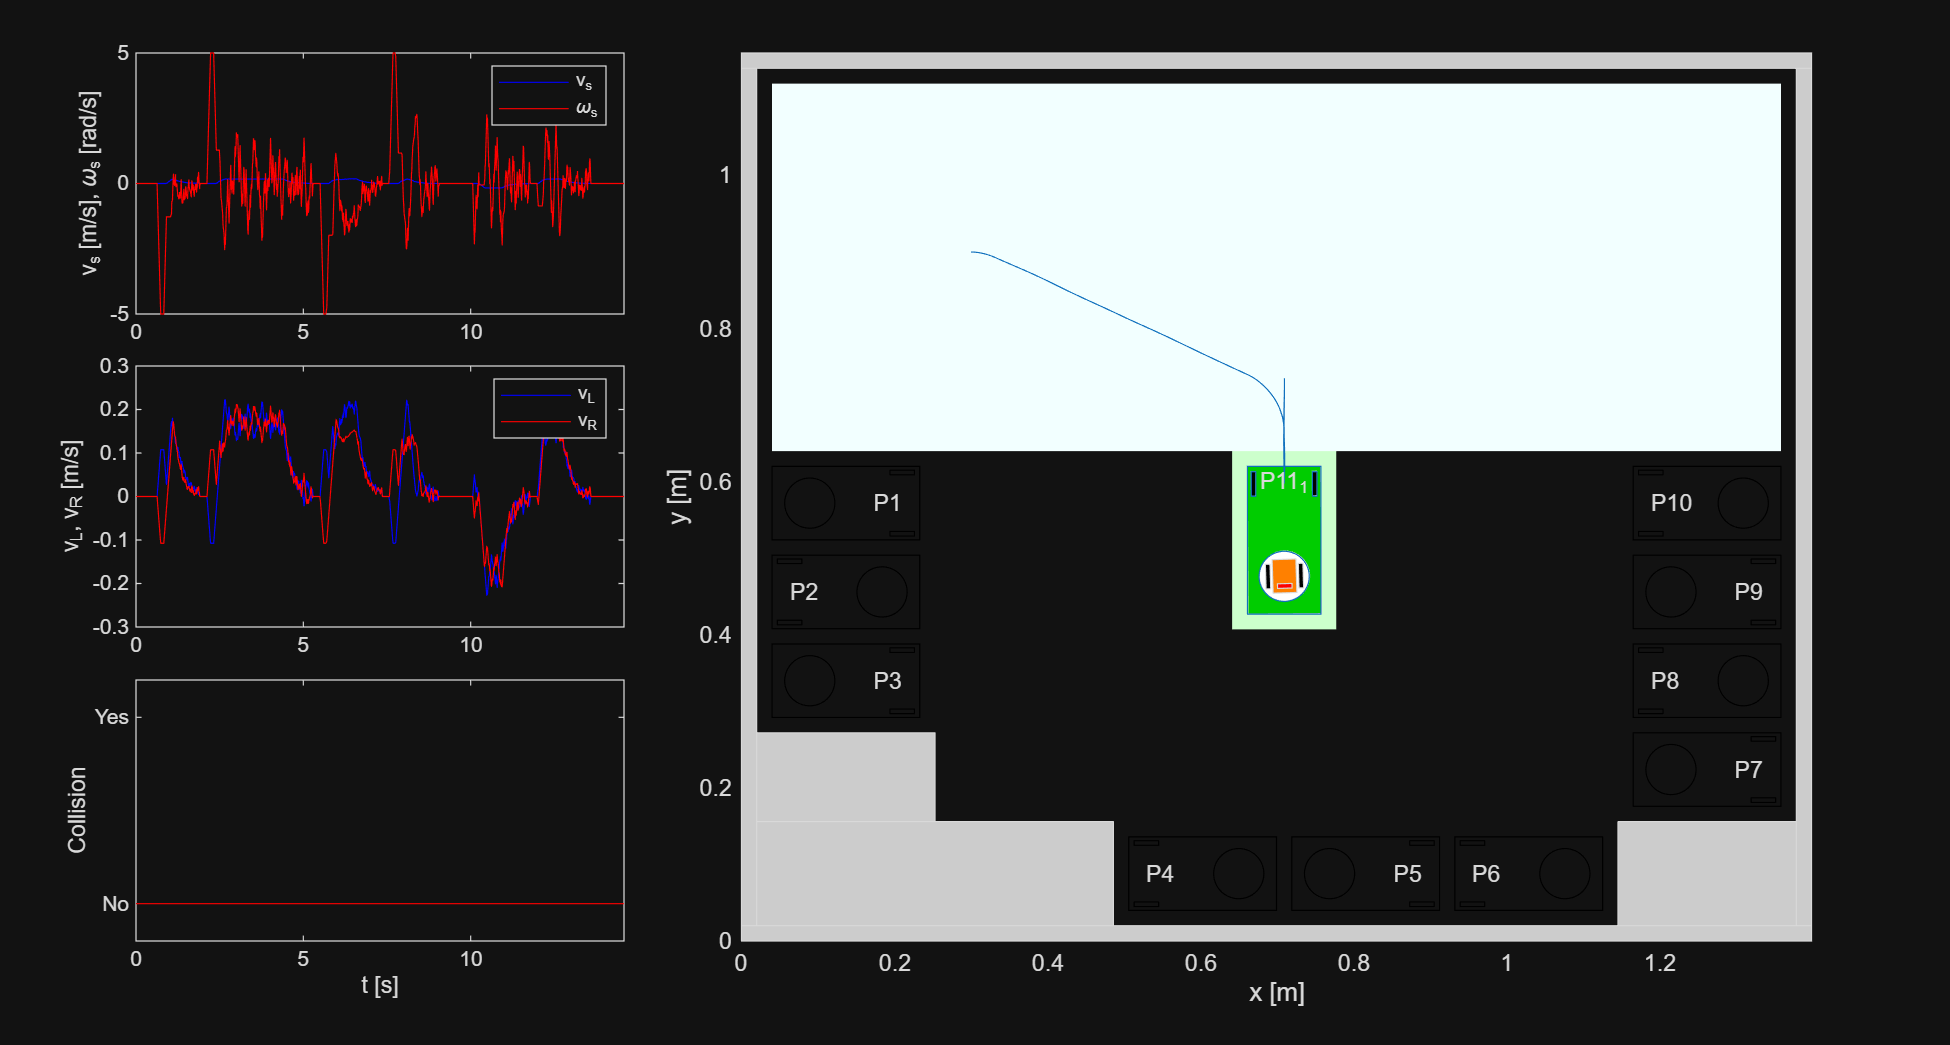


# Summary
 - Robot 1: inside=1, ed=  0.0004 m, ephi= -0.0050 rad, t= 14.5800 s


data = simParking(qA, 11, noise, anima);

store('ex1case1', data);
reportCase(data, 1);

    Spot    Error_mm    Error_deg    Time_s    Path_m     WheelEffort_m2_s    Collisions    MeetsTarget
    ____    ________    _________    ______    _______    ________________    __________    ___________

     11     0.43477      0.28749     14.58     0.83387        0.29026             0              1     



### Case 2: From the known initial configuration B to P11

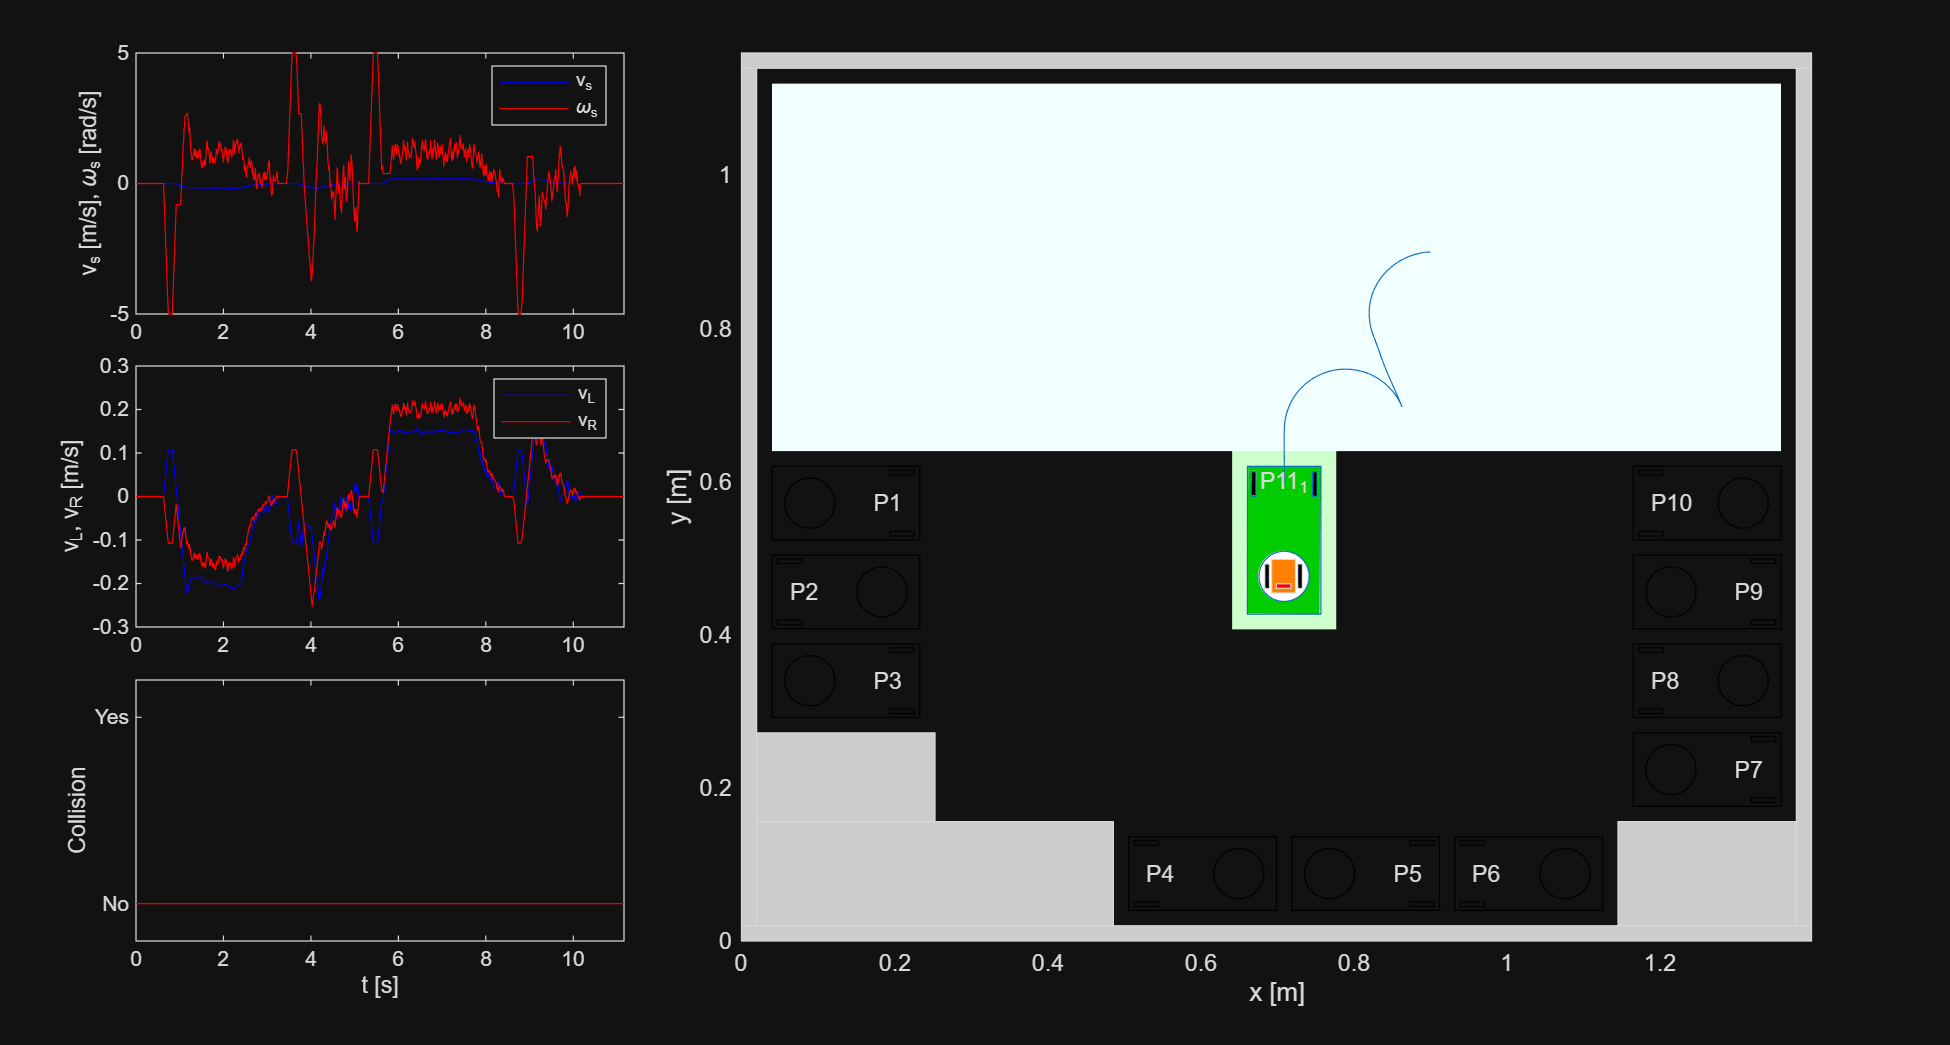


# Summary
 - Robot 1: inside=1, ed=  0.0003 m, ephi=  0.0080 rad, t= 11.1600 s


data = simParking(qB, 11, noise, anima);

store('ex1case2', data);
reportCase(data, 1);

    Spot    Error_mm    Error_deg    Time_s    Path_m     WheelEffort_m2_s    Collisions    MeetsTarget
    ____    ________    _________    ______    _______    ________________    __________    ___________

     11     0.29371      0.45674     11.16     0.54446        0.28309             0              1     



### Case 3: From the known initial configuration C to P11

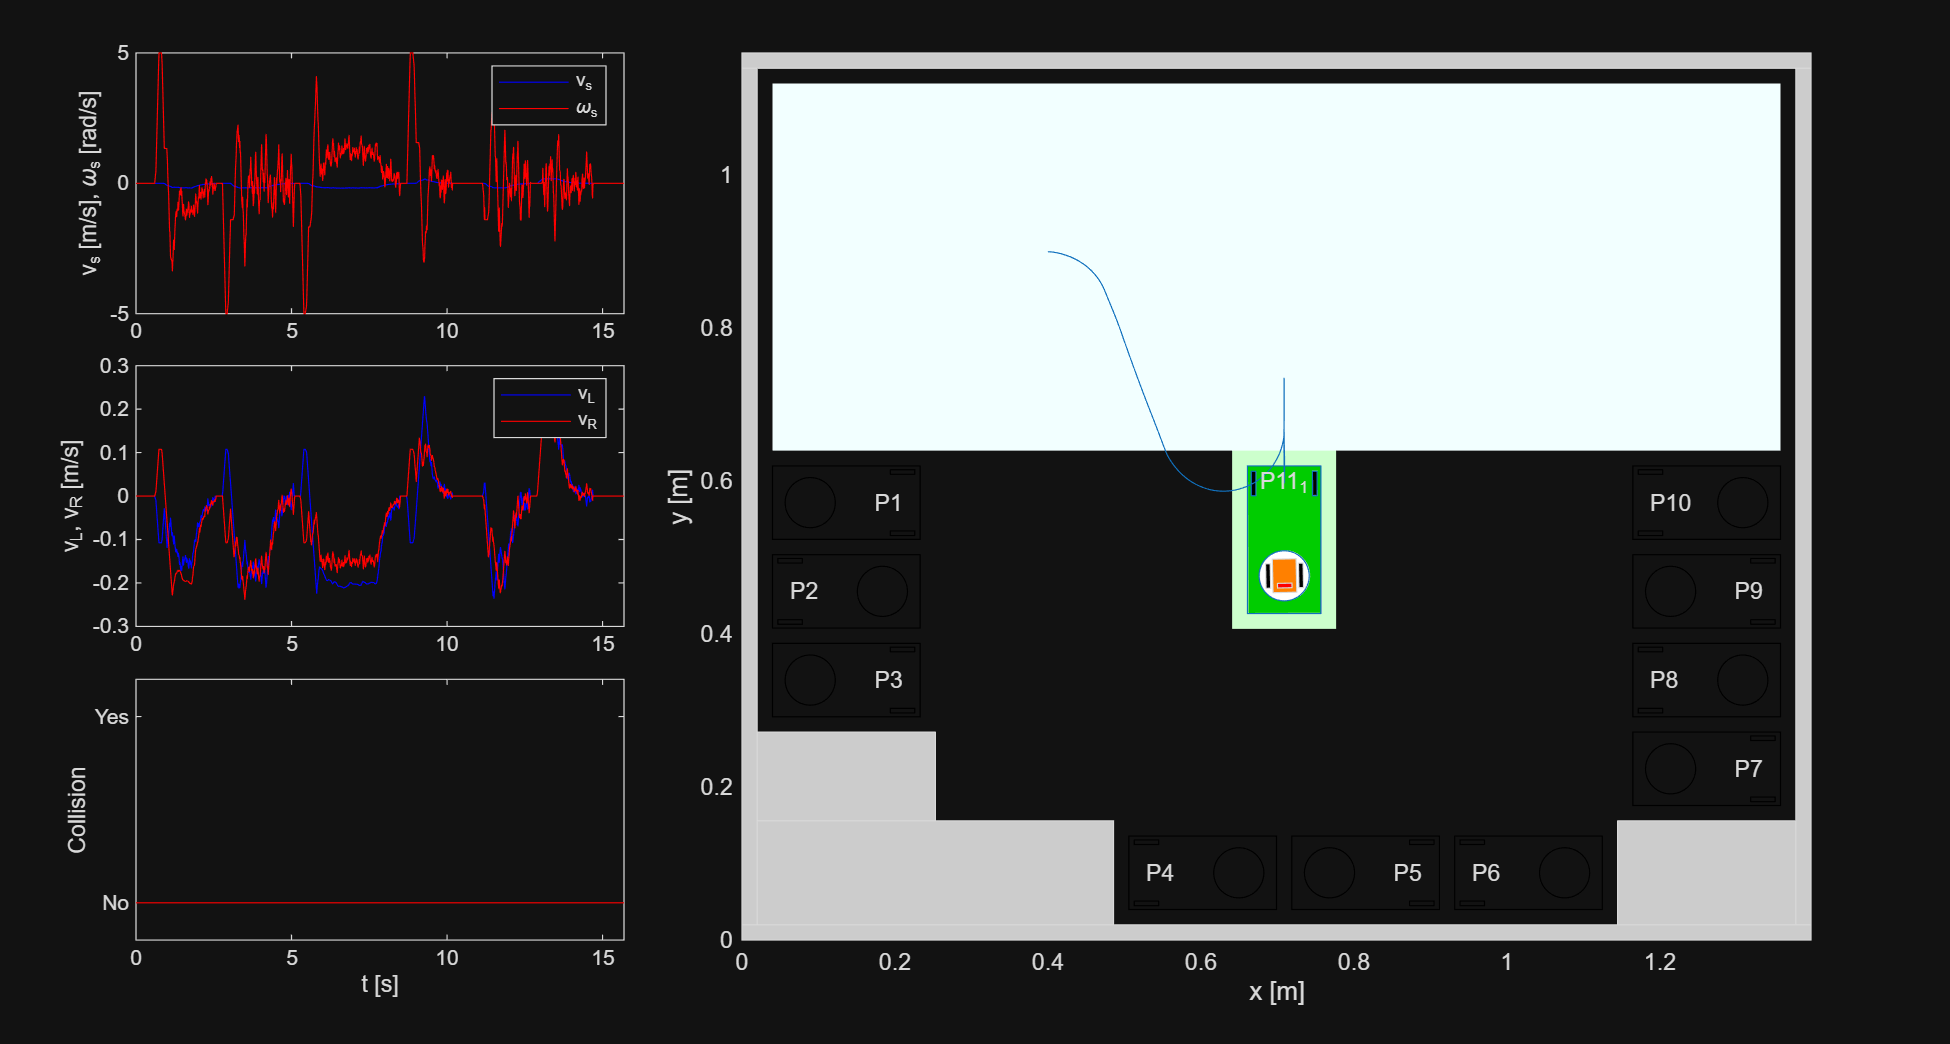


# Summary
 - Robot 1: inside=1, ed=  0.0002 m, ephi= -0.0039 rad, t= 15.6900 s


data = simParking(qC, 11, noise, anima);

store('ex1case3', data);
reportCase(data, 1);

    Spot    Error_mm    Error_deg    Time_s    Path_m     WheelEffort_m2_s    Collisions    MeetsTarget
    ____    ________    _________    ______    _______    ________________    __________    ___________

     11     0.17433      0.22083     15.69     0.88554        0.36307             0              1     



### Case 4: From the known initial configuration D to P11

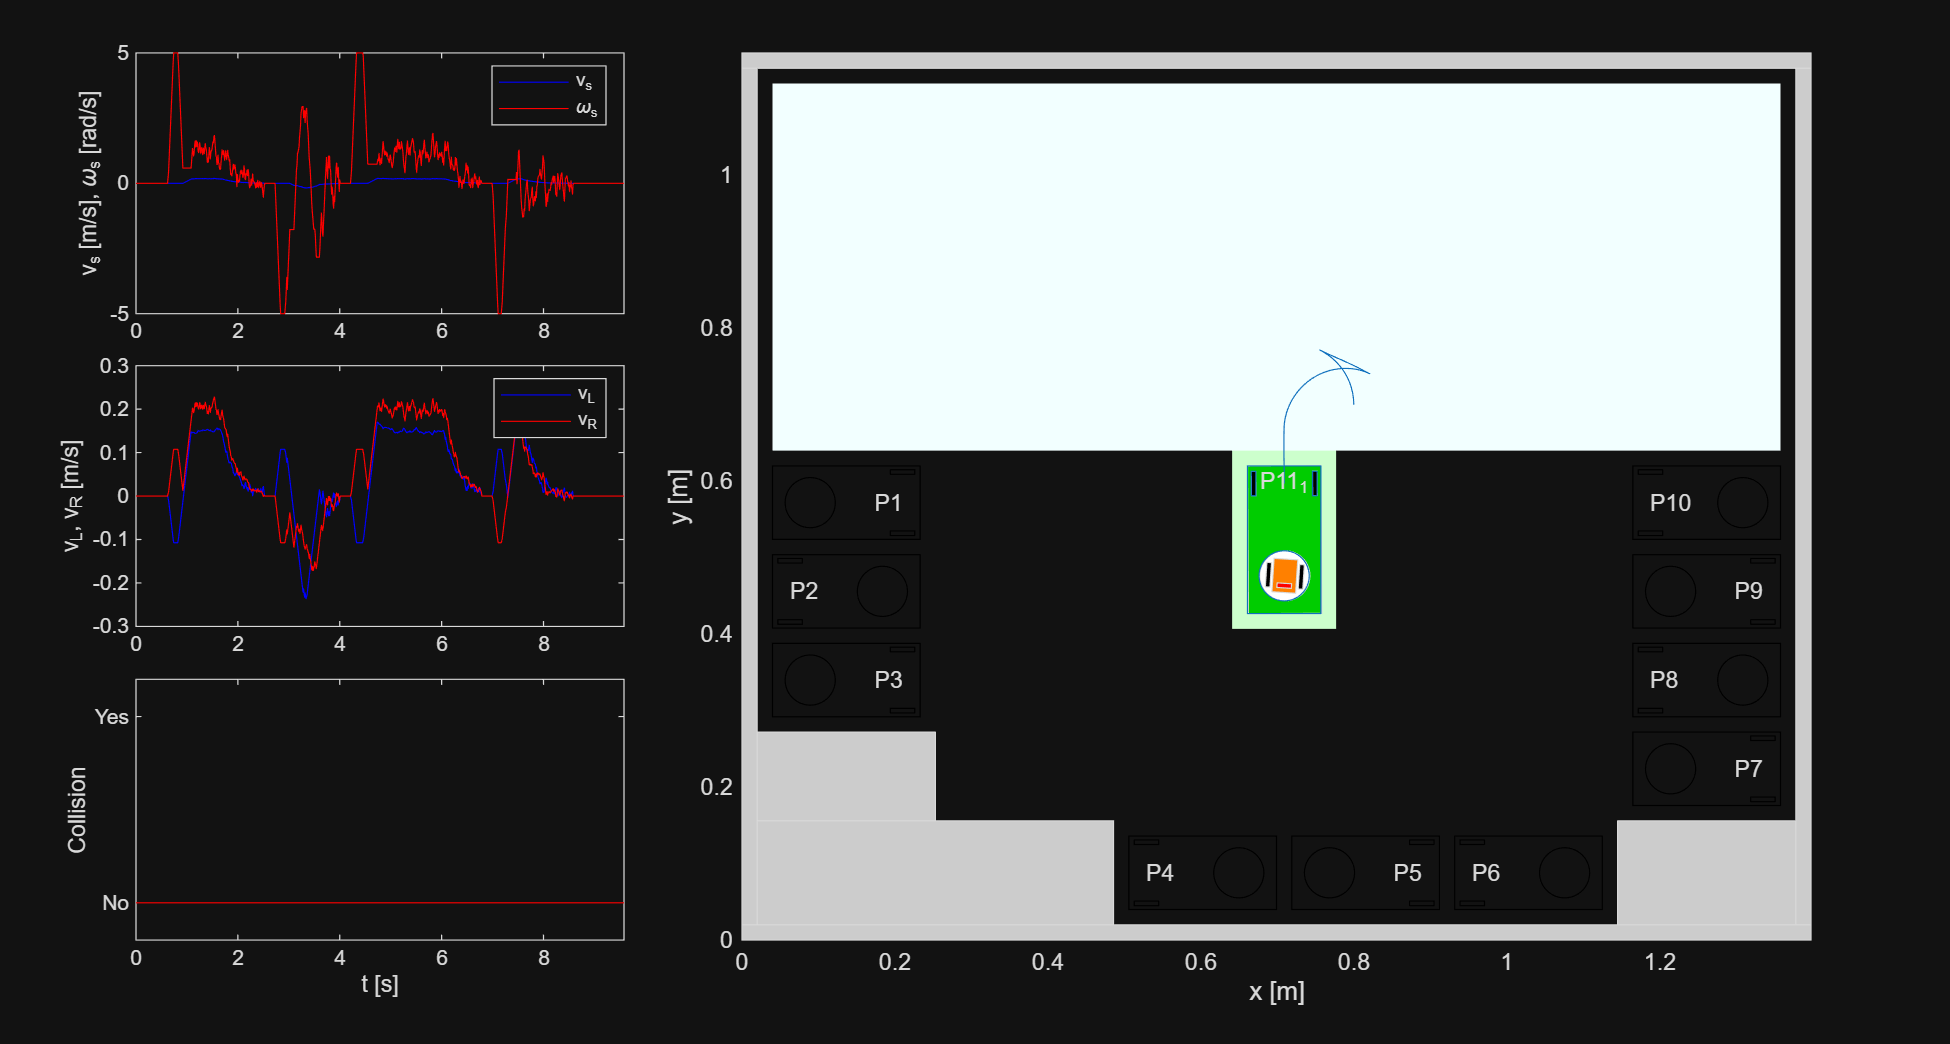


# Summary
 - Robot 1: inside=1, ed=  0.0002 m, ephi= -0.0060 rad, t=  9.5800 s


data = simParking(qD, 11, noise, anima);

store('ex1case4', data);
reportCase(data, 1);

    Spot    Error_mm    Error_deg    Time_s    Path_m     WheelEffort_m2_s    Collisions    MeetsTarget
    ____    ________    _________    ______    _______    ________________    __________    ___________

     11     0.18636      0.34522      9.58     0.39326        0.19717             0              1     



### Case 5: From the known initial configuration A to P1

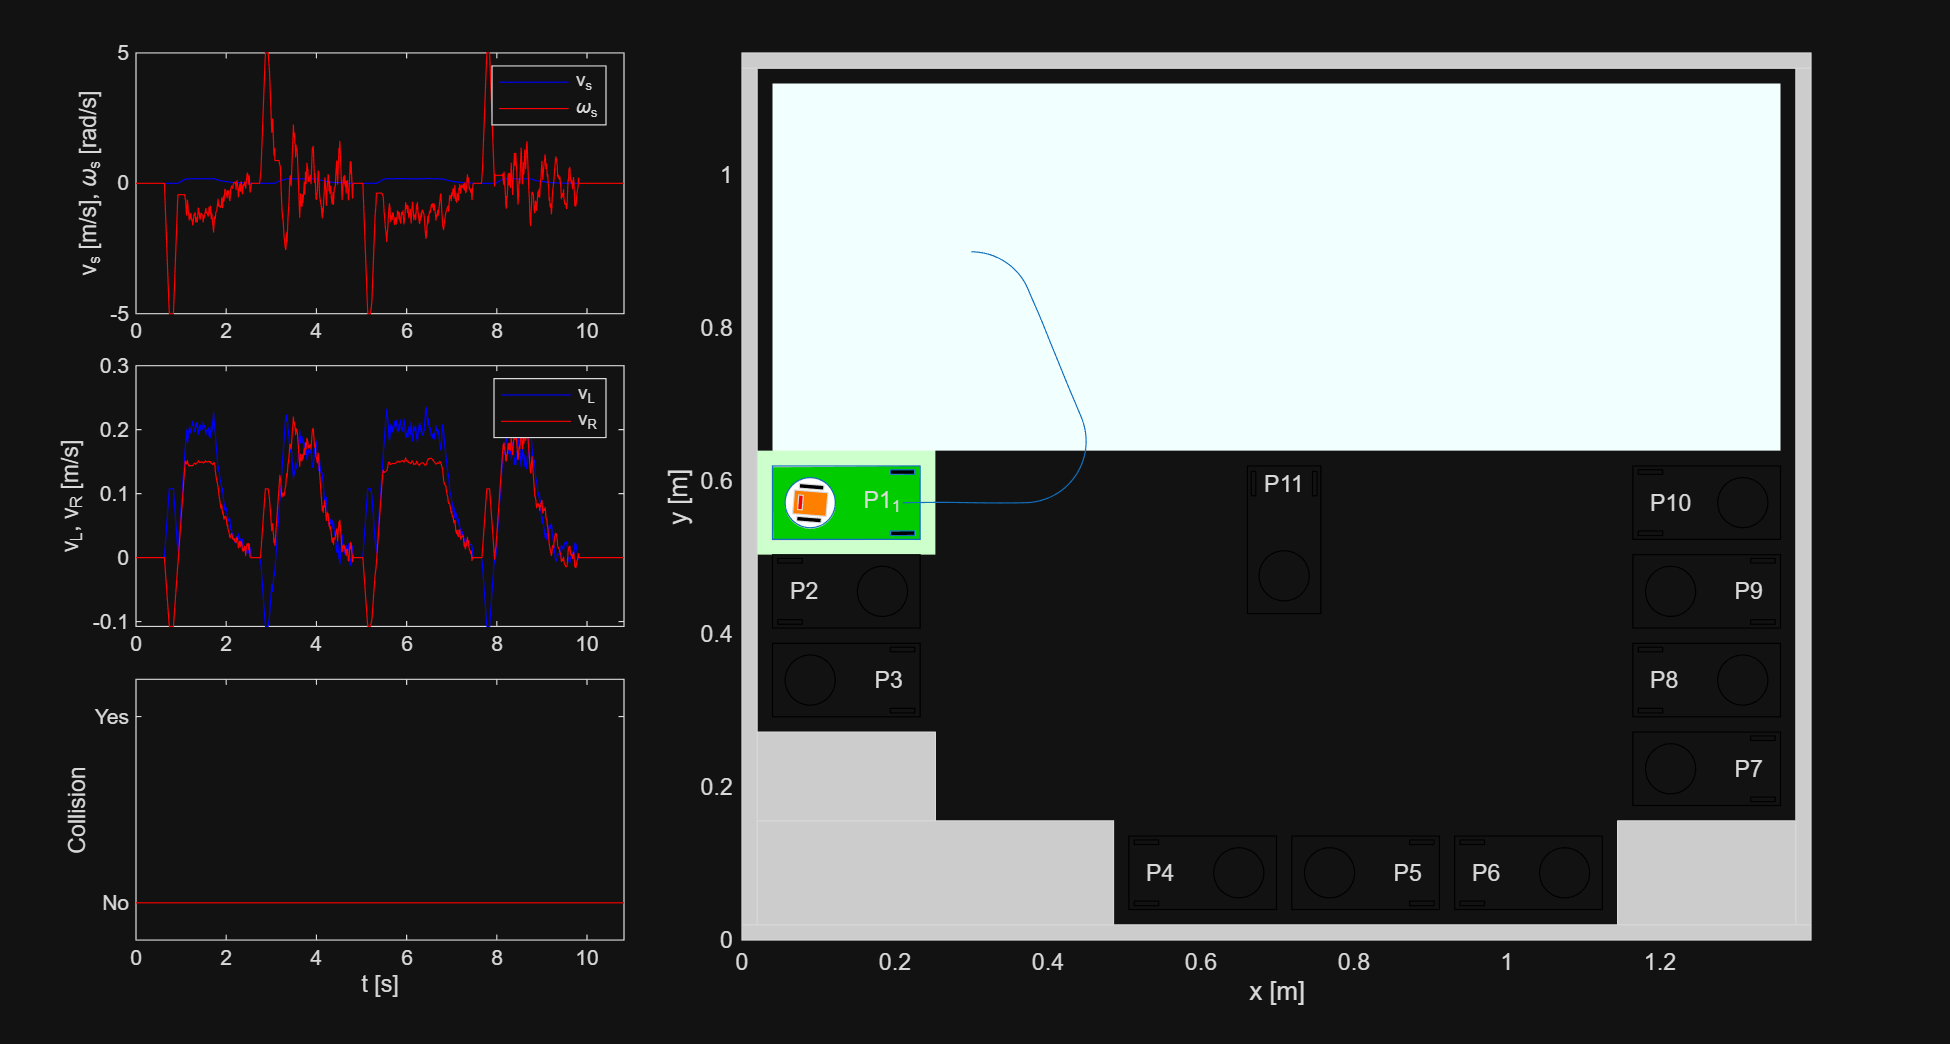


# Summary
 - Robot 1: inside=1, ed=  0.0001 m, ephi= -0.0058 rad, t= 10.8200 s


data = simParking(qA, 1, noise, anima);

store('ex1case5', data);
reportCase(data, 1);

    Spot    Error_mm    Error_deg    Time_s    Path_m     WheelEffort_m2_s    Collisions    MeetsTarget
    ____    ________    _________    ______    _______    ________________    __________    ___________

     1      0.076118     0.33474     10.82     0.59345        0.25895             0              1     



### Case 6: From the known initial configuration A to P7

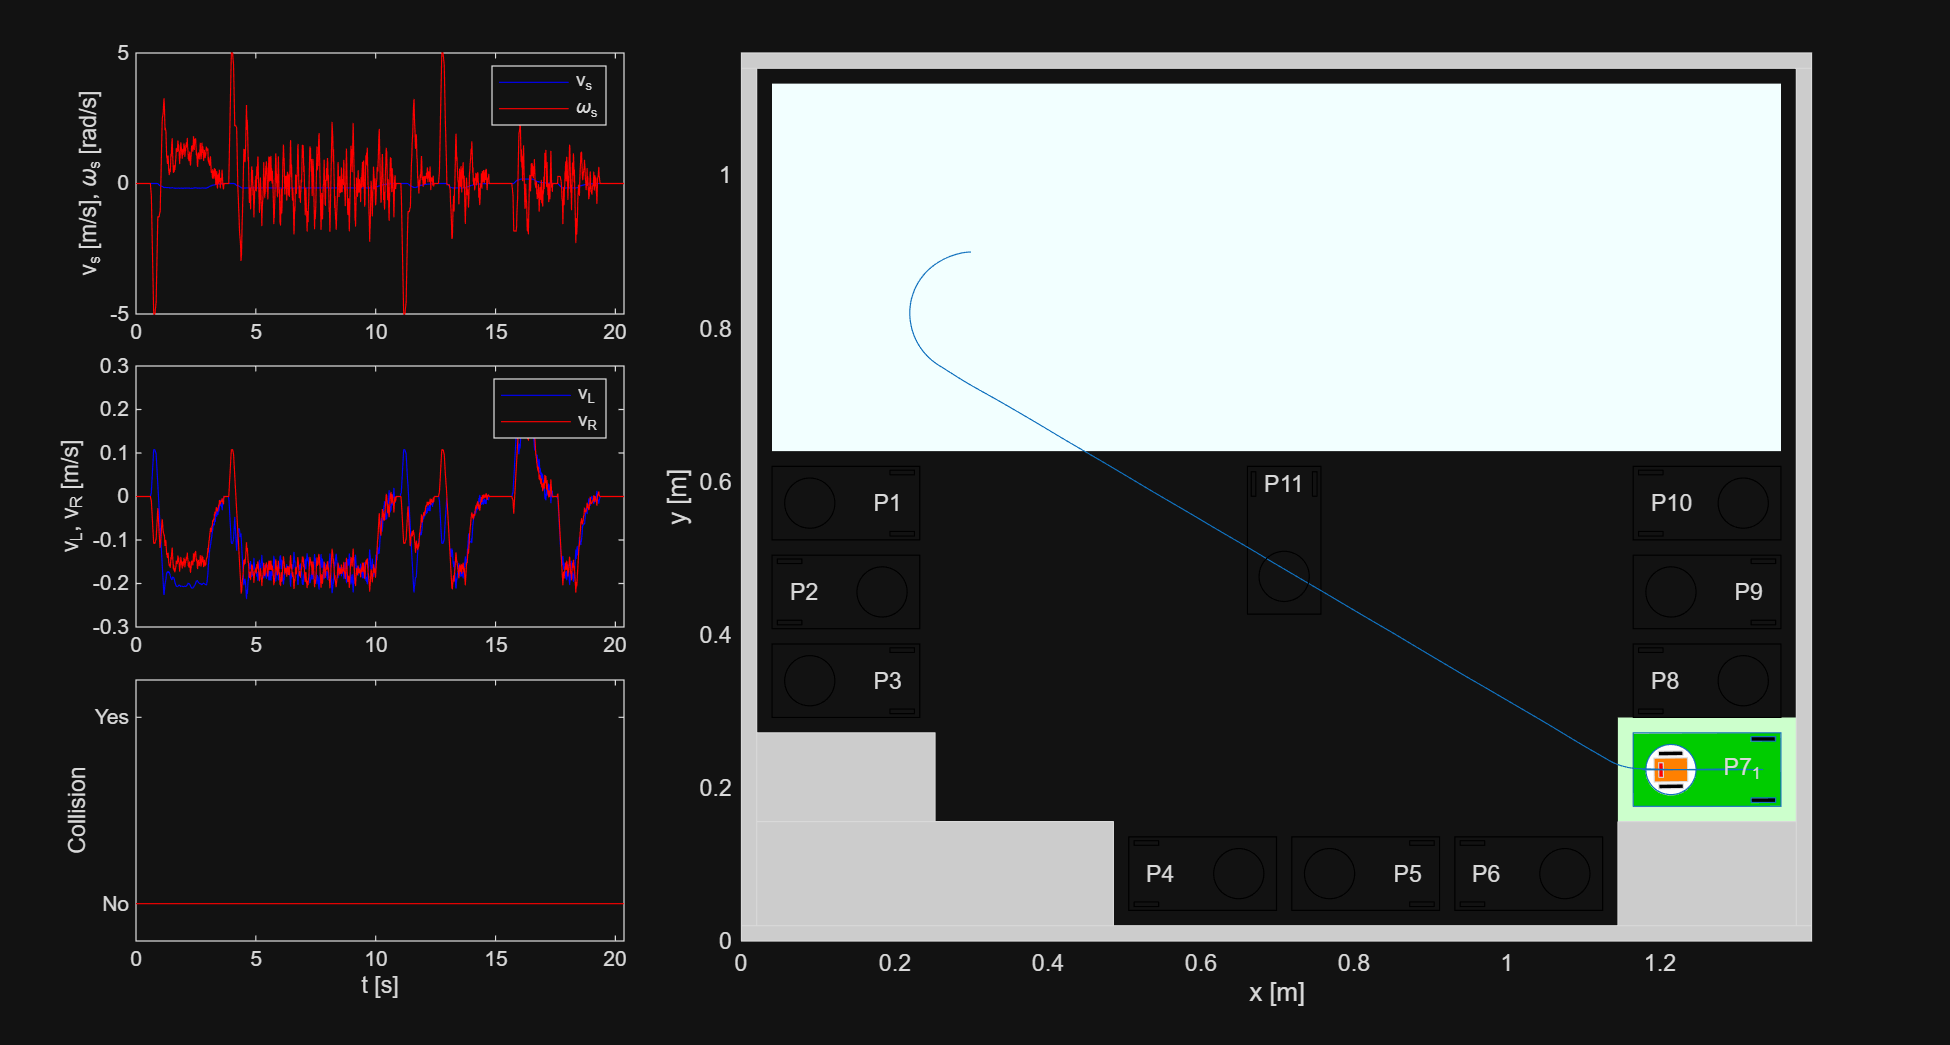


# Summary
 - Robot 1: inside=1, ed=  0.0001 m, ephi= -0.0037 rad, t= 20.3600 s


data = simParking(qA, 7, noise, anima);

store('ex1case6', data);
reportCase(data, 1);

    Spot    Error_mm    Error_deg    Time_s    Path_m    WheelEffort_m2_s    Collisions    MeetsTarget
    ____    ________    _________    ______    ______    ________________    __________    ___________

     7      0.11869      0.21238     20.36     1.7436        0.63859             0              1     



### Case 7: From the known initial configuration A to P5

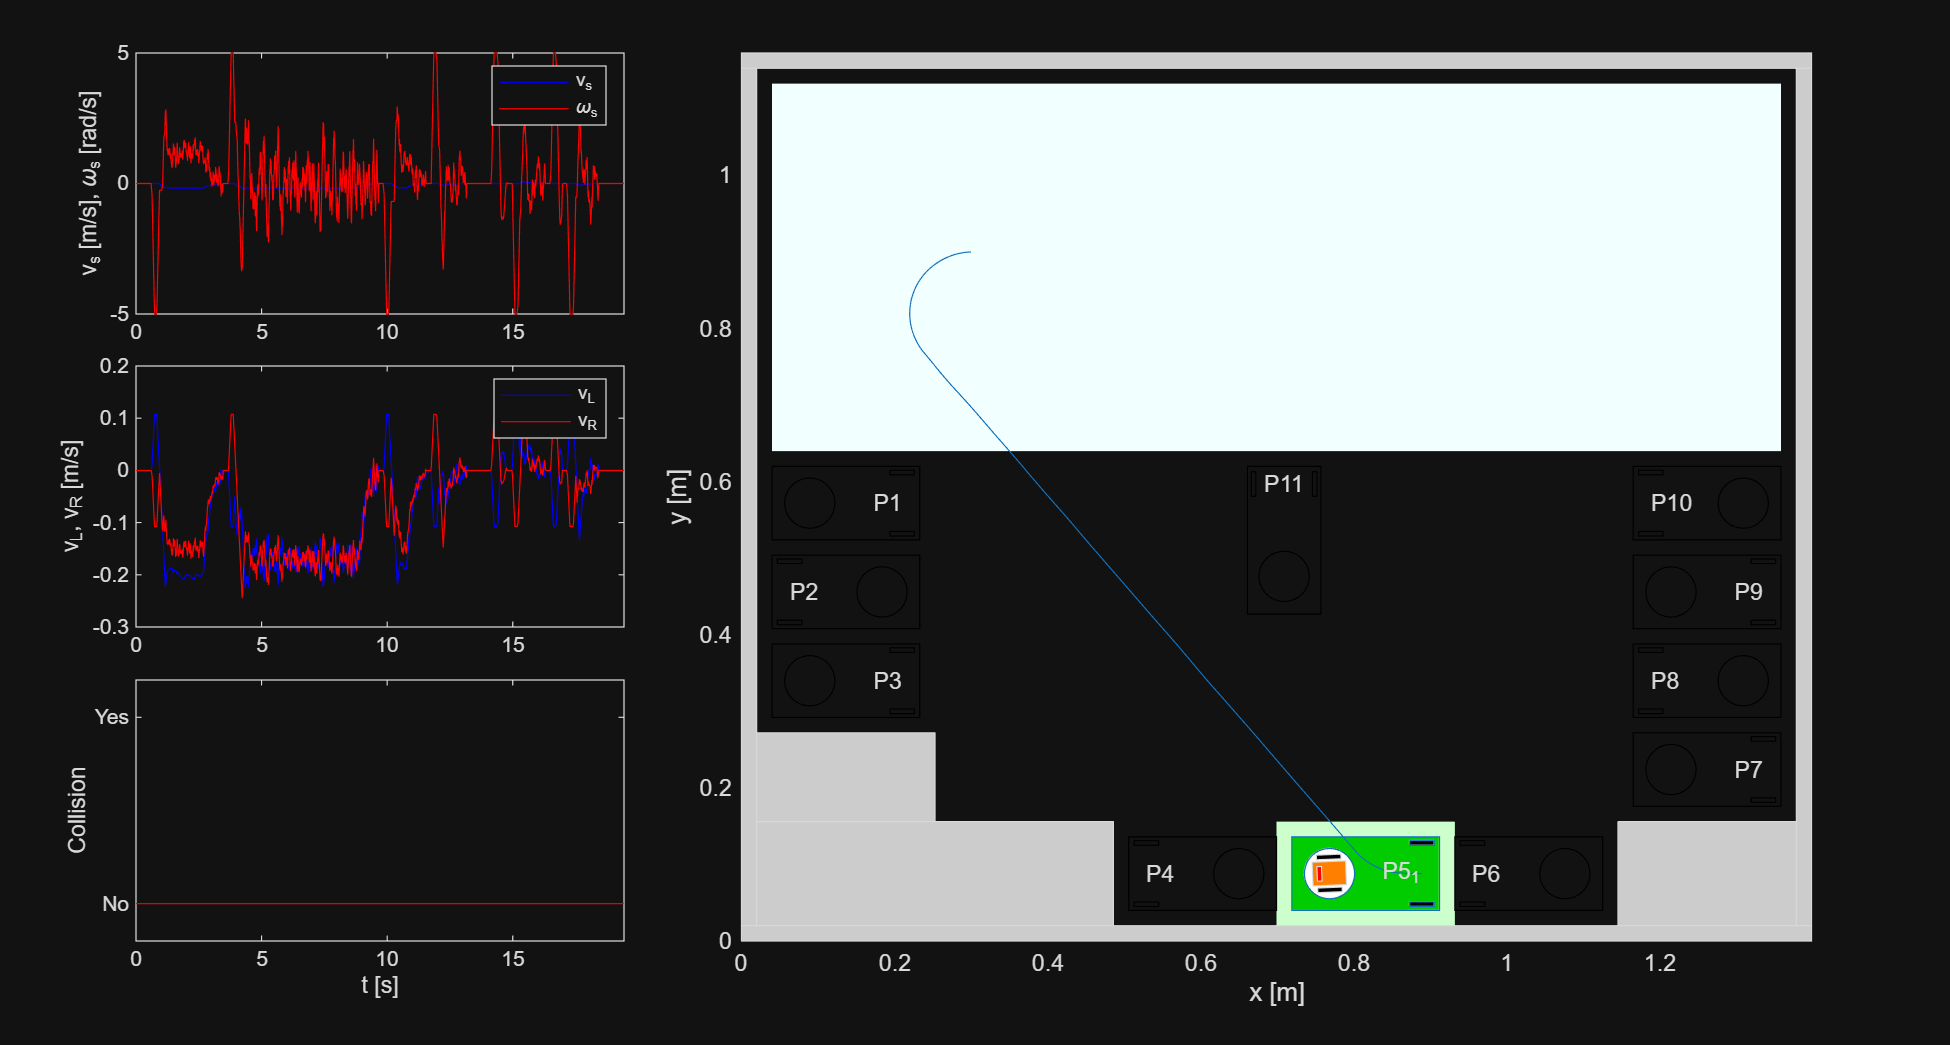


# Summary
 - Robot 1: inside=1, ed=  0.0004 m, ephi= -0.0002 rad, t= 19.4300 s


data = simParking(qA, 5, noise, anima);

store('ex1case7', data);
reportCase(data, 1);

    Spot    Error_mm    Error_deg    Time_s    Path_m    WheelEffort_m2_s    Collisions    MeetsTarget
    ____    ________    _________    ______    ______    ________________    __________    ___________

     5      0.43367     0.013815     19.43     1.186         0.47373             0              1     



### Case 8: From a random initial configuration to a random parking spot

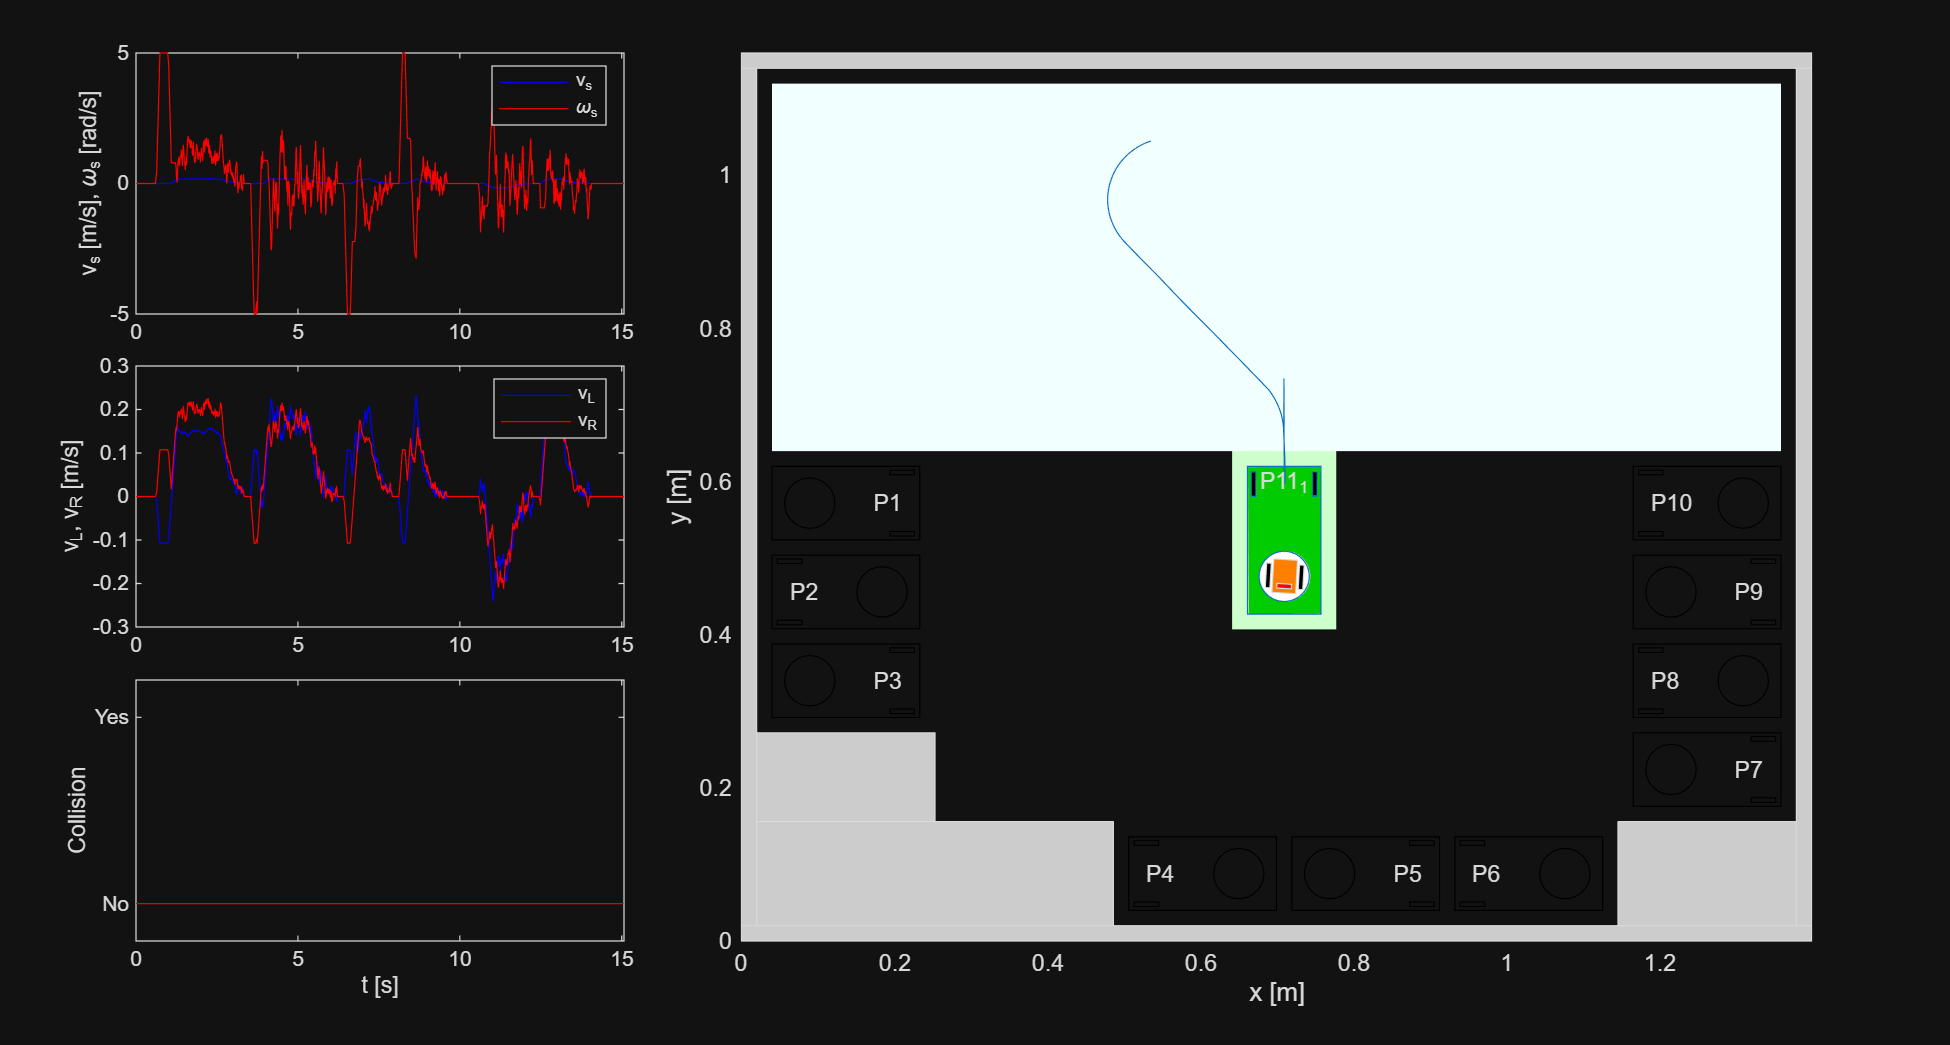


# Summary
 - Robot 1: inside=1, ed=  0.0001 m, ephi= -0.0056 rad, t= 15.0700 s


data = simParking([], 0, noise, anima);

store('ex1case8', data);
reportCase(data, 1);

    Spot    Error_mm    Error_deg    Time_s    Path_m     WheelEffort_m2_s    Collisions    MeetsTarget
    ____    ________    _________    ______    _______    ________________    __________    ___________

     11     0.098219     0.31847     15.07     0.83602        0.32184             0              1     



## Exercise 2: Multiple robots

Each robot starts with fresh controller state. The controller checks the predefined approaches against the footprints of the robots that have already parked. The bottom row uses short predefined forward and reverse moves when neighboring robots leave little room.

### Case 1: From the same known initial configuration S to P1, P8, P10, P3 and P6

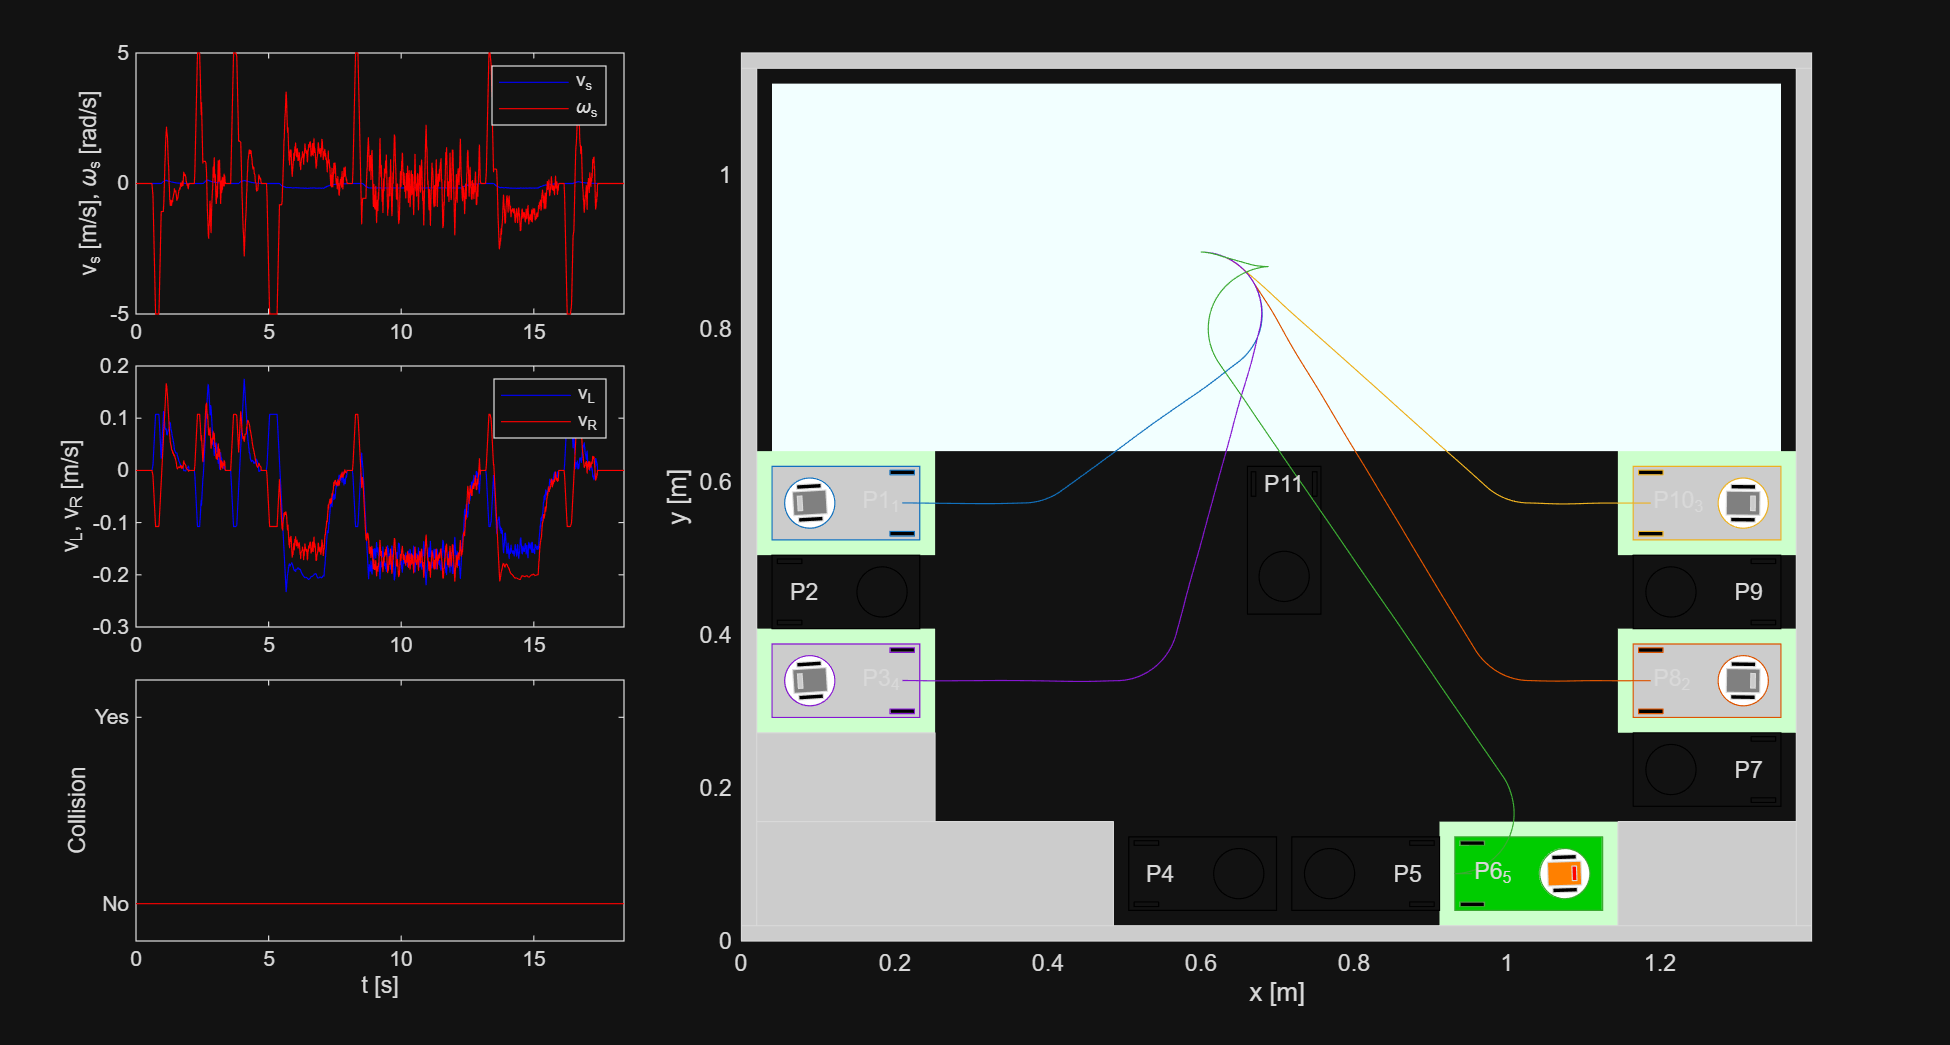


# Summary
 - Robot 1: inside=1, ed=  0.0003 m, ephi=  0.0012 rad, t= 11.4000 s
 - Robot 2: inside=1, ed=  0.0001 m, ephi= -0.0003 rad, t= 12.3300 s
 - Robot 3: inside=1, ed=  0.0001 m, ephi=  0.0016 rad, t= 10.8400 s
 - Robot 4: inside=1, ed=  0.0005 m, ephi=  0.0003 rad, t= 12.6900 s
 - Robot 5: inside=1, ed=  0.0004 m, ephi= -0.0007 rad, t= 18.4000 s


data = simParking(qS, [1, 8, 10, 3, 6], noise, anima);

store('ex2case1', data);
reportCase(data, 5);

    Spot    Error_mm    Error_deg    Time_s    Path_m     WheelEffort_m2_s    Collisions    MeetsTarget
    ____    ________    _________    ______    _______    ________________    __________    ___________

      1      0.26622    0.068625      11.4     0.69615        0.29517             0              1     
      8     0.094796    0.016675     12.33     0.88728        0.33549             0              1     
     10      0.14397     0.09407     10.84     0.70751        0.25903             0              1     
      3      0.48836    0.016726     12.69     0.94539        0.38227             0              1     
      6      0.39291    0.040843      18.4      1.1172        0.47889             0              1     



### Case 2: From the same known initial configuration S to P2, P9, P7 and P4

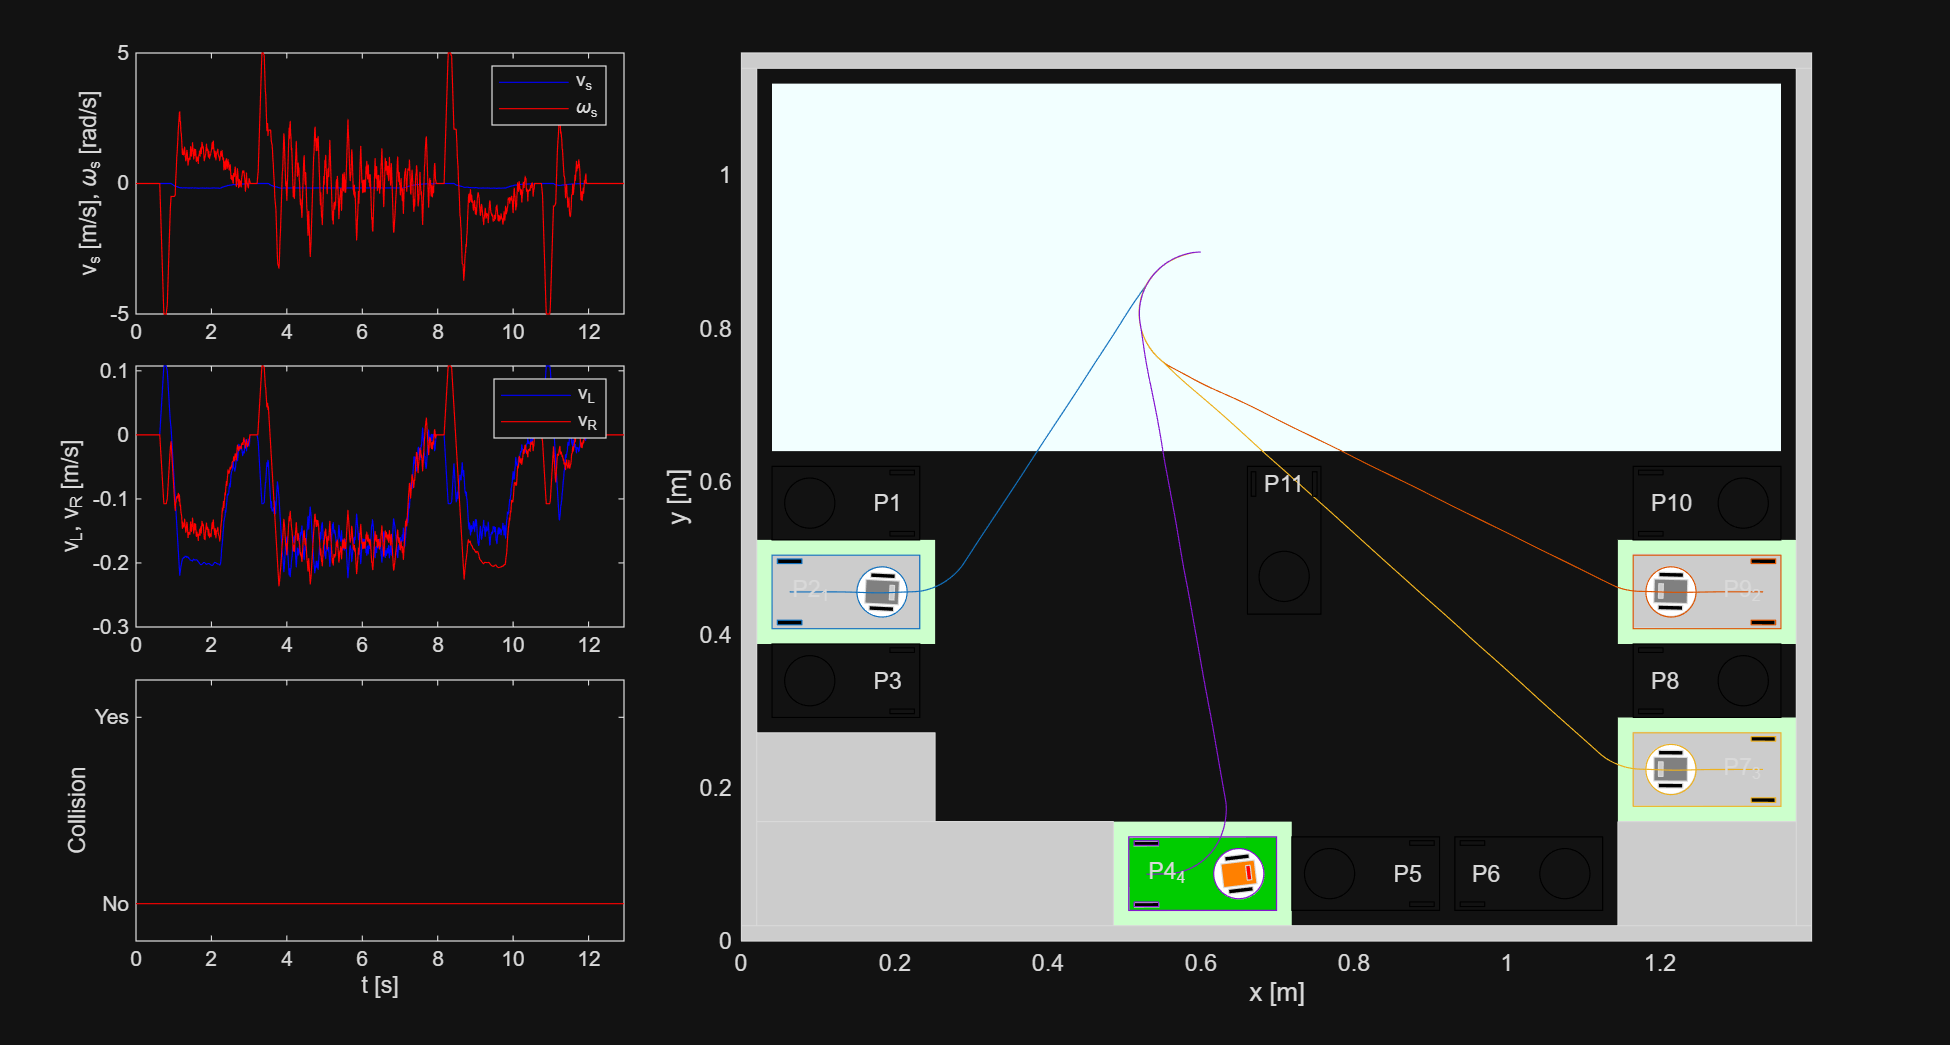


# Summary
 - Robot 1: inside=1, ed=  0.0002 m, ephi=  0.0026 rad, t= 11.3500 s
 - Robot 2: inside=1, ed=  0.0003 m, ephi=  0.0066 rad, t= 13.6100 s
 - Robot 3: inside=1, ed=  0.0005 m, ephi=  0.0031 rad, t= 14.2300 s
 - Robot 4: inside=1, ed=  0.0007 m, ephi= -0.0033 rad, t= 12.9400 s


data = simParking(qS, [2, 9, 7, 4], noise, anima);

store('ex2case2', data);
reportCase(data, 4);

    Spot    Error_mm    Error_deg    Time_s    Path_m     WheelEffort_m2_s    Collisions    MeetsTarget
    ____    ________    _________    ______    _______    ________________    __________    ___________

     2      0.15202      0.14836     11.35     0.76159         0.2863             0              1     
     9      0.29035        0.378     13.61      1.0522        0.41874             0              1     
     7      0.45604      0.17947     14.23      1.1832        0.46318             0              1     
     4      0.74981      0.18992     12.94     0.93703        0.38789             0              1     



### Case 3: From the same known initial configuration S to P1, P3, P10, P8, P6, P2, P7, P9, P4 and P5

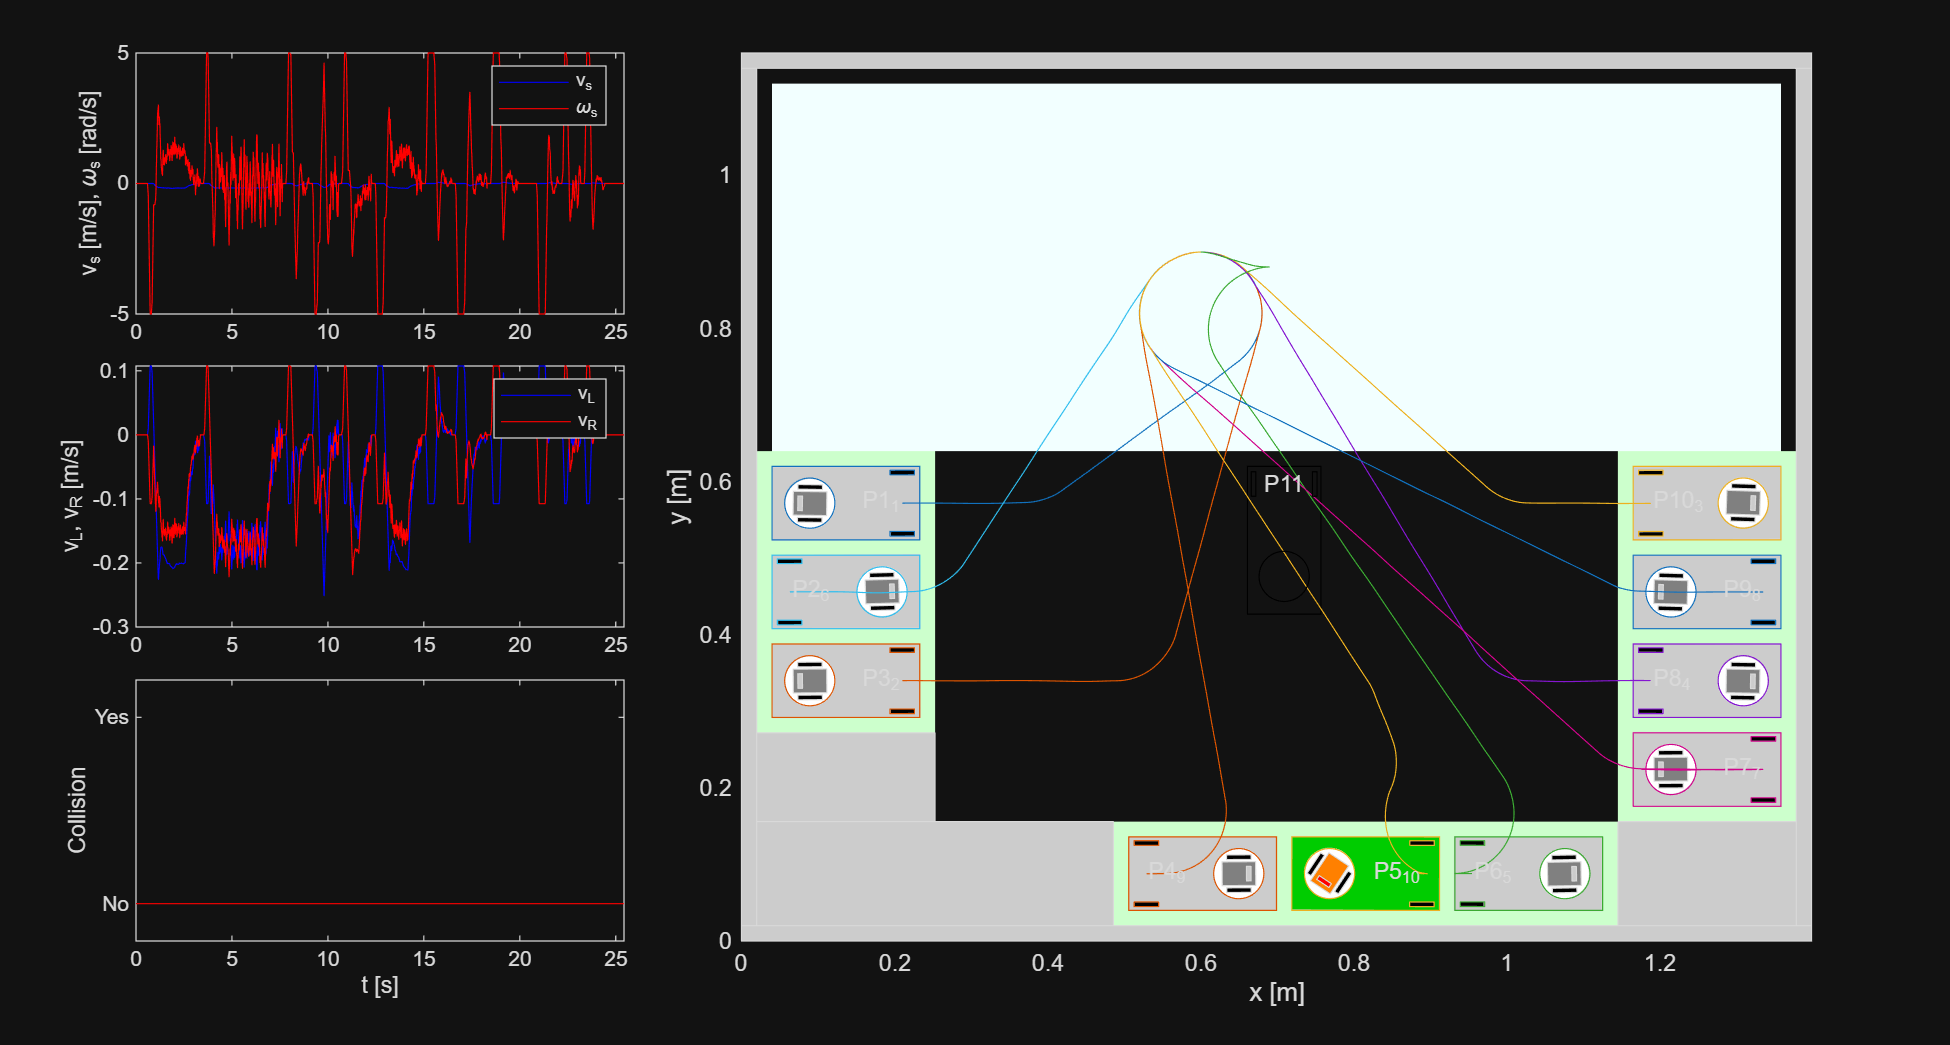


# Summary
 - Robot 1: inside=1, ed=  0.0003 m, ephi= -0.0038 rad, t= 11.5000 s
 - Robot 2: inside=1, ed=  0.0003 m, ephi= -0.0035 rad, t= 12.8800 s
 - Robot 3: inside=1, ed=  0.0003 m, ephi= -0.0070 rad, t= 11.0600 s
 - Robot 4: inside=1, ed=  0.0004 m, ephi=  0.0064 rad, t= 12.1300 s
 - Robot 5: inside=1, ed=  0.0007 m, ephi=  0.0034 rad, t= 18.5200 s
 - Robot 6: inside=1, ed=  0.0003 m, ephi= -0.0042 rad, t= 11.3600 s
 - Robot 7: inside=1, ed=  0.0002 m, ephi=  0.0021 rad, t= 19.1900 s
 - Robot 8: inside=1, ed=  0.0003 m, ephi= -0.0004 rad, t= 13.5600 s
 - Robot 9: inside=1, ed=  0.0002 m, ephi= -0.0002 rad, t= 17.9300 s
 - Robot 10: inside=1, ed=  0.0001 m, ephi=  0.0040 rad, t= 25.4300 s


data = simParking(qS, [1, 3, 10, 8, 6, 2, 7, 9, 4, 5], noise, anima);

store('ex2case3', data);
reportCase(data, 10);

    Spot    Error_mm    Error_deg    Time_s    Path_m     WheelEffort_m2_s    Collisions    MeetsTarget
    ____    ________    _________    ______    _______    ________________    __________    ___________

      1     0.26451       0.21872     11.5     0.69612        0.29391             0              1     
      3     0.34263       0.20167    12.88     0.94532        0.38008             0              1     
     10     0.30342        0.4004    11.06     0.70816        0.25735             0              1     
      8     0.35727       0.36911    12.13      0.8876        0.33593             0              1     
      6     0.69901       0.19592    18.52      1.1179        0.48233             0              1     
      2     0.26889       0.24152    11.36     0.76154        0.29243             0              1     
      7     0.24857       0.12001    19.19      1.4999         0.5567             0              1     
      9     0.30946      0.023928    13.56      1.0515        0

### Case 4: From the same known initial configuration S to P11, P1, P2, P9, P10, P5, P3, P8, P7, P4 and P6

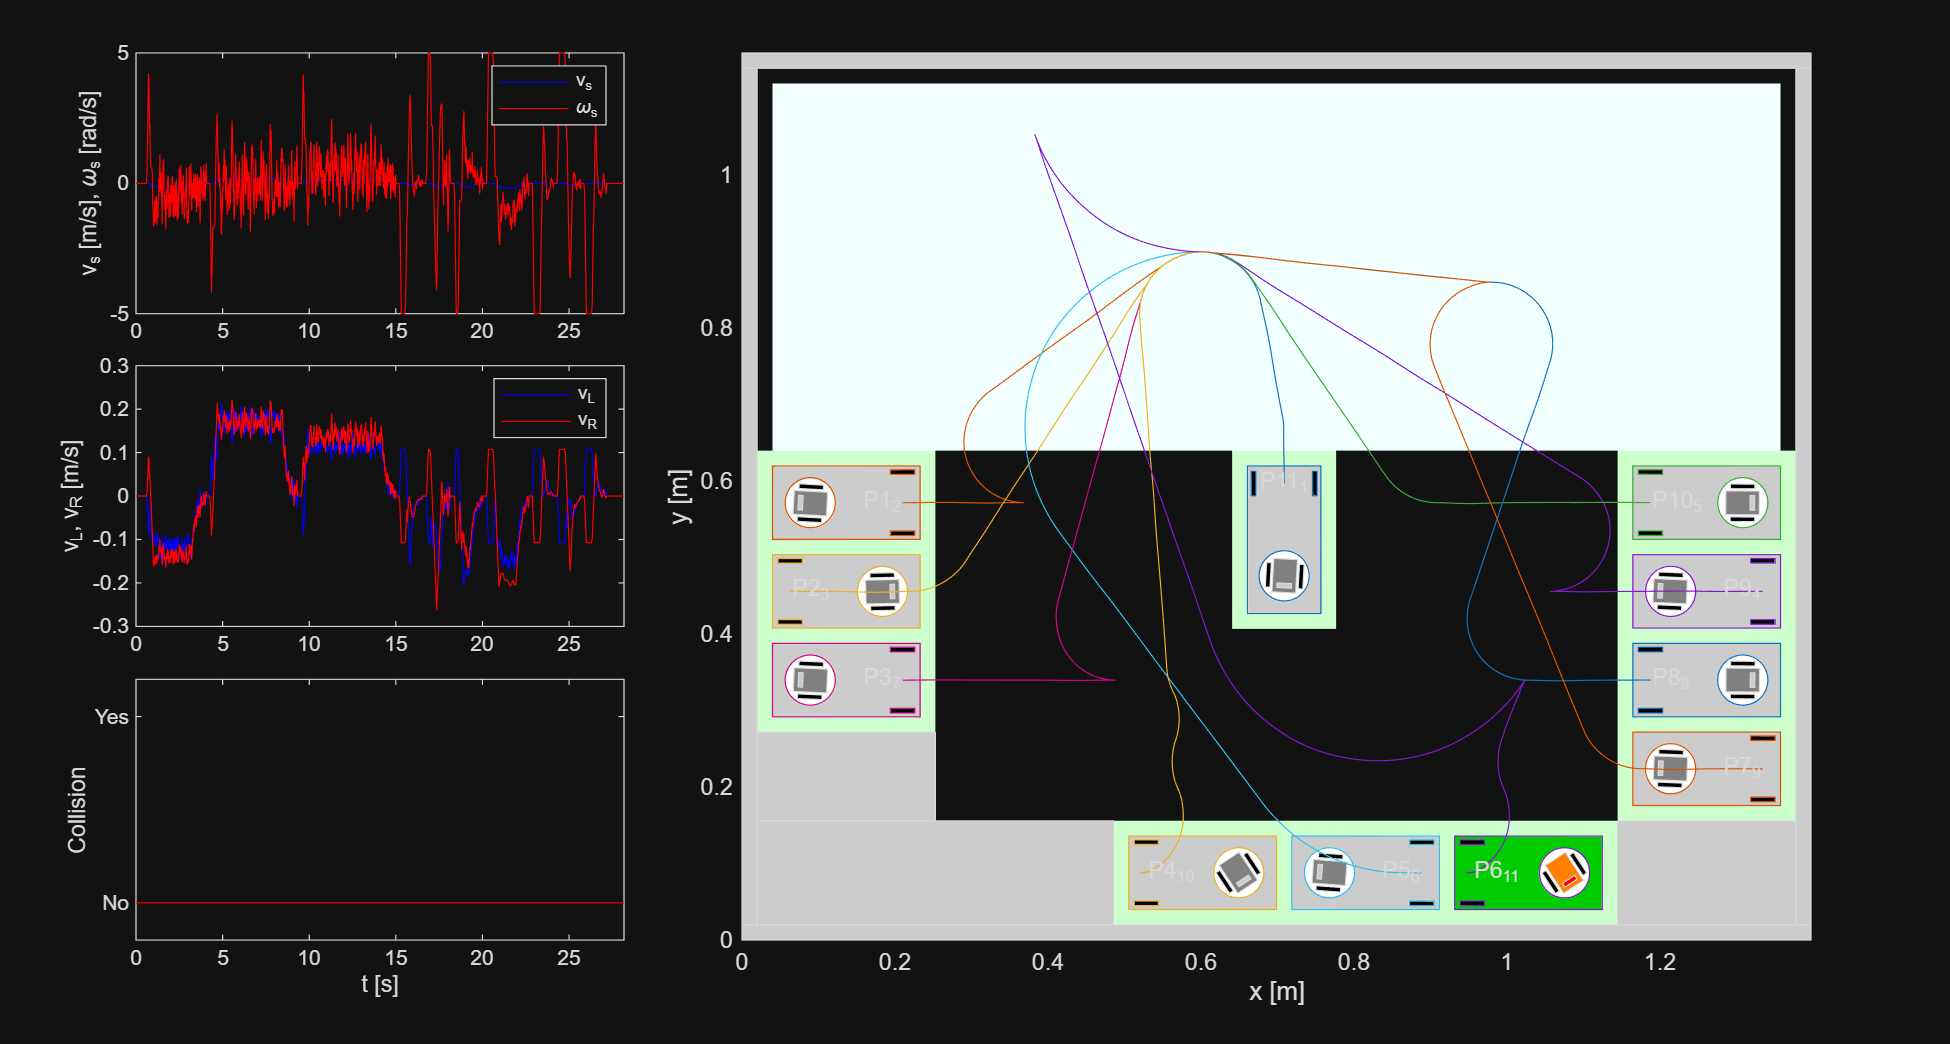


# Summary
 - Robot 1: inside=1, ed=  0.0002 m, ephi= -0.0050 rad, t=  8.7800 s
 - Robot 2: inside=1, ed=  0.0002 m, ephi= -0.0055 rad, t= 11.2600 s
 - Robot 3: inside=1, ed=  0.0002 m, ephi=  0.0034 rad, t= 11.4900 s
 - Robot 4: inside=1, ed=  0.0006 m, ephi=  0.0005 rad, t= 13.5000 s
 - Robot 5: inside=1, ed=  0.0003 m, ephi=  0.0029 rad, t= 11.3000 s
 - Robot 6: inside=1, ed=  0.0002 m, ephi=  0.0044 rad, t= 15.1800 s
 - Robot 7: inside=1, ed=  0.0003 m, ephi= -0.0017 rad, t= 12.8700 s
 - Robot 8: inside=1, ed=  0.0001 m, ephi= -0.0005 rad, t= 18.1400 s
 - Robot 9: inside=1, ed=  0.0002 m, ephi=  0.0040 rad, t= 18.7500 s
 - Robot 10: inside=1, ed=  0.0006 m, ephi=  0.0003 rad, t= 20.7700 s
 - Robot 11: inside=1, ed=  0.0002 m, ephi=  0.0020 rad, t= 28.1700 s


data = simParking(qS, [11, 1, 2, 9, 10, 5, 3, 8, 7, 4, 6], noise, anima);

store('ex2case4', data);
reportCase(data, 11);

    Spot    Error_mm    Error_deg    Time_s    Path_m     WheelEffort_m2_s    Collisions    MeetsTarget
    ____    ________    _________    ______    _______    ________________    __________    ___________

     11      0.20452     0.28685      8.78     0.35086        0.14345             0              1     
      1      0.22047     0.31398     11.26     0.69255        0.29346             0              1     
      2      0.16764     0.19644     11.49     0.76156        0.28989             0              1     
      9      0.60234    0.026624      13.5      1.0647        0.42479             0              1     
     10      0.32596     0.16816      11.3      0.7476         0.2847             0              1     
      5      0.15684      0.2514     15.18      1.1871        0.35273             0              1     
      3      0.32729    0.099141     12.87     0.94257        0.37871             0              1     
      8     0.094578    0.031139     18.14      1.1714         

### Case 5: From random initial configurations to random parking spots

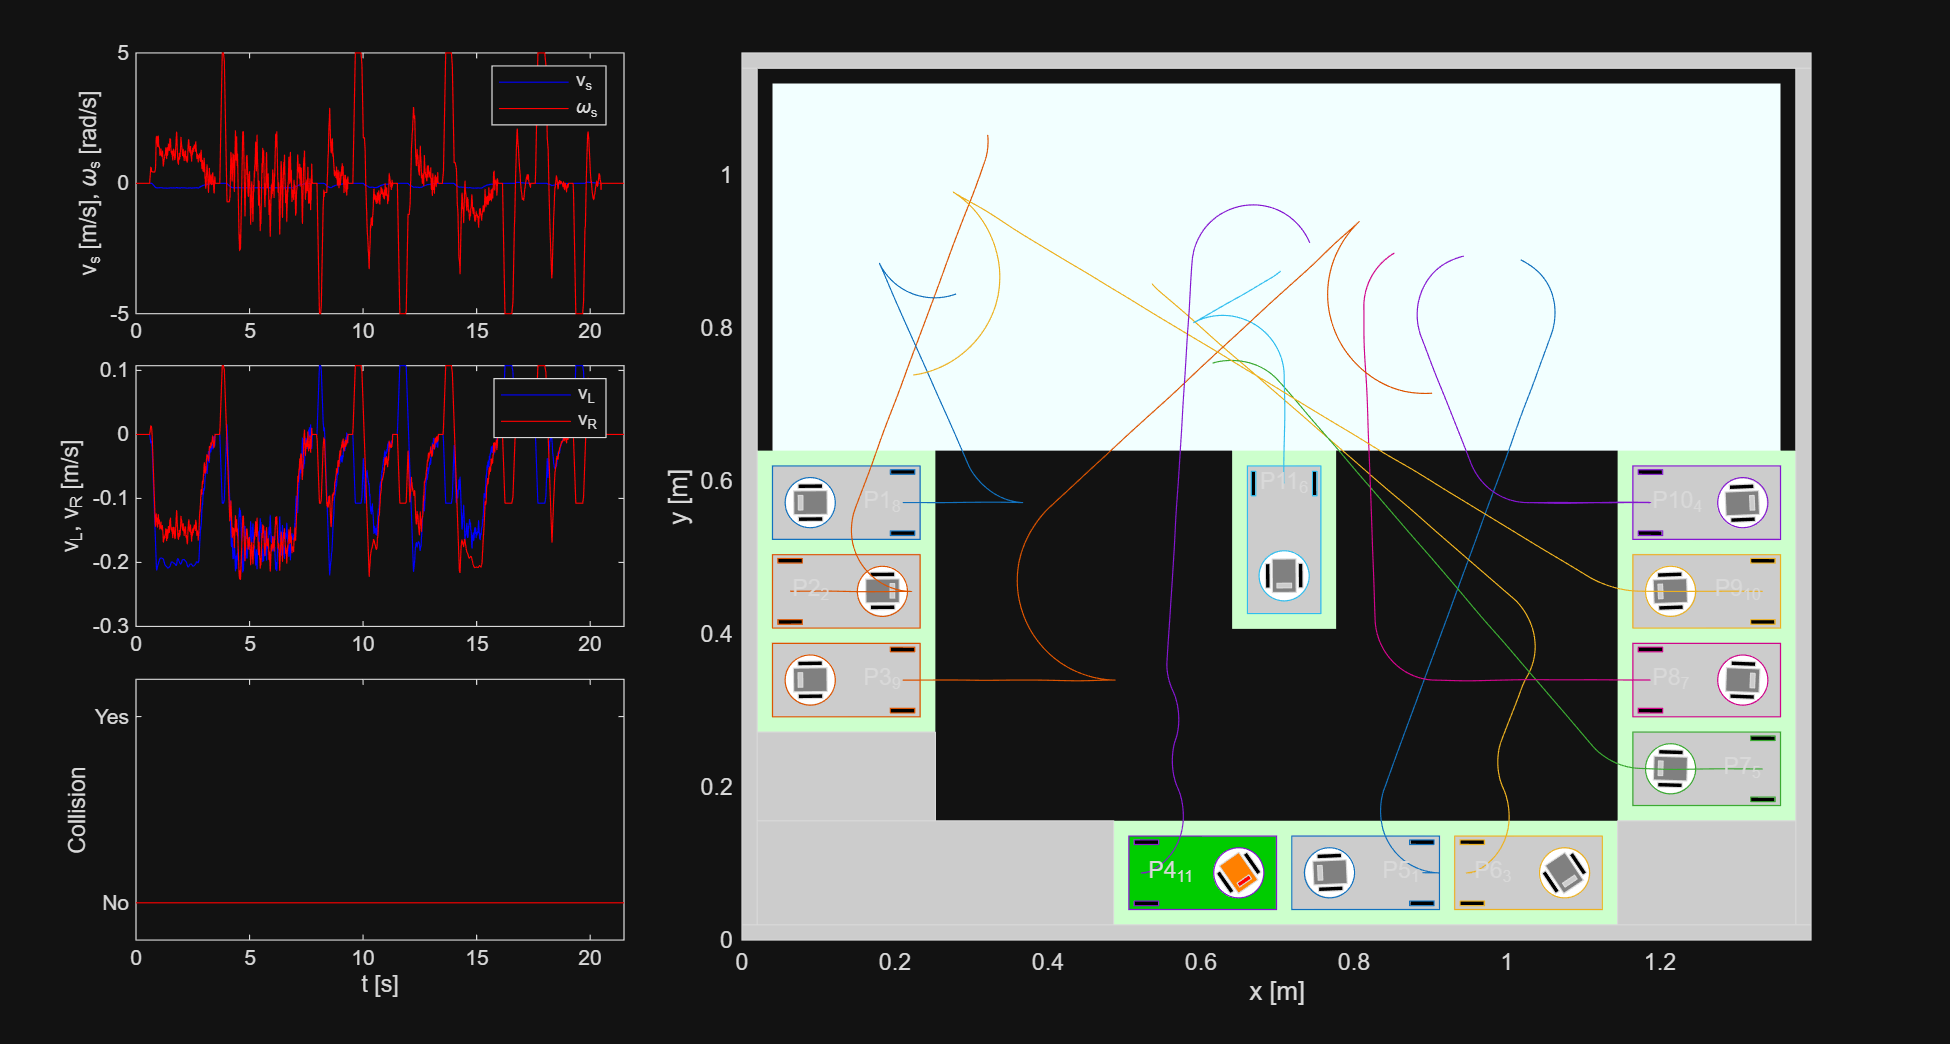


# Summary
 - Robot 1: inside=1, ed=  0.0007 m, ephi=  0.0038 rad, t= 13.2600 s
 - Robot 2: inside=1, ed=  0.0002 m, ephi= -0.0042 rad, t= 12.1100 s
 - Robot 3: inside=1, ed=  0.0004 m, ephi=  0.0027 rad, t= 22.6300 s
 - Robot 4: inside=1, ed=  0.0006 m, ephi=  0.0063 rad, t= 15.6800 s
 - Robot 5: inside=1, ed=  0.0003 m, ephi=  0.0041 rad, t= 12.9400 s
 - Robot 6: inside=1, ed=  0.0004 m, ephi= -0.0036 rad, t=  9.6100 s
 - Robot 7: inside=1, ed=  0.0001 m, ephi=  0.0013 rad, t= 12.5700 s
 - Robot 8: inside=1, ed=  0.0003 m, ephi= -0.0008 rad, t= 11.5300 s
 - Robot 9: inside=1, ed=  0.0001 m, ephi=  0.0032 rad, t= 17.6000 s
 - Robot 10: inside=1, ed=  0.0003 m, ephi=  0.0028 rad, t= 16.4100 s
 - Robot 11: inside=1, ed=  0.0002 m, ephi=  0.0005 rad, t= 21.4900 s


data = simParking([], [0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0], noise, anima);

store('ex2case5', data);
reportCase(data, 11);

    Spot    Error_mm    Error_deg    Time_s    Path_m     WheelEffort_m2_s    Collisions    MeetsTarget
    ____    ________    _________    ______    _______    ________________    __________    ___________

      5      0.69001     0.21665     13.26     0.92702         0.3933             0              1     
      2      0.22521       0.239     12.11     0.83232        0.32458             0              1     
      6      0.35573     0.15249     22.63      1.0518         0.4683             0              1     
     10      0.59709      0.3631     15.68     0.88599        0.34763             0              1     
      7      0.28778     0.23422     12.94     0.95513        0.36459             0              1     
     11      0.40758     0.20386      9.61     0.43865        0.18649             0              1     
      8     0.085161    0.076717     12.57     0.89869         0.3614             0              1     
      1      0.33957    0.048329     11.53     0.65929        0

## Exercise 3: Limited steering angle gamma

The steering reference is bounded by plus or minus 30 degrees. The turning radius follows from kappa = tan(gamma)/D. The reference arcs leave two degrees of steering margin. The front-unit command is omega_s = v_s sin(gamma)/D + 14 (gamma_ref - gamma), with the angle error wrapped.

### Case 1: From the same known initial configuration S to P1, P8, P10, P3 and P6

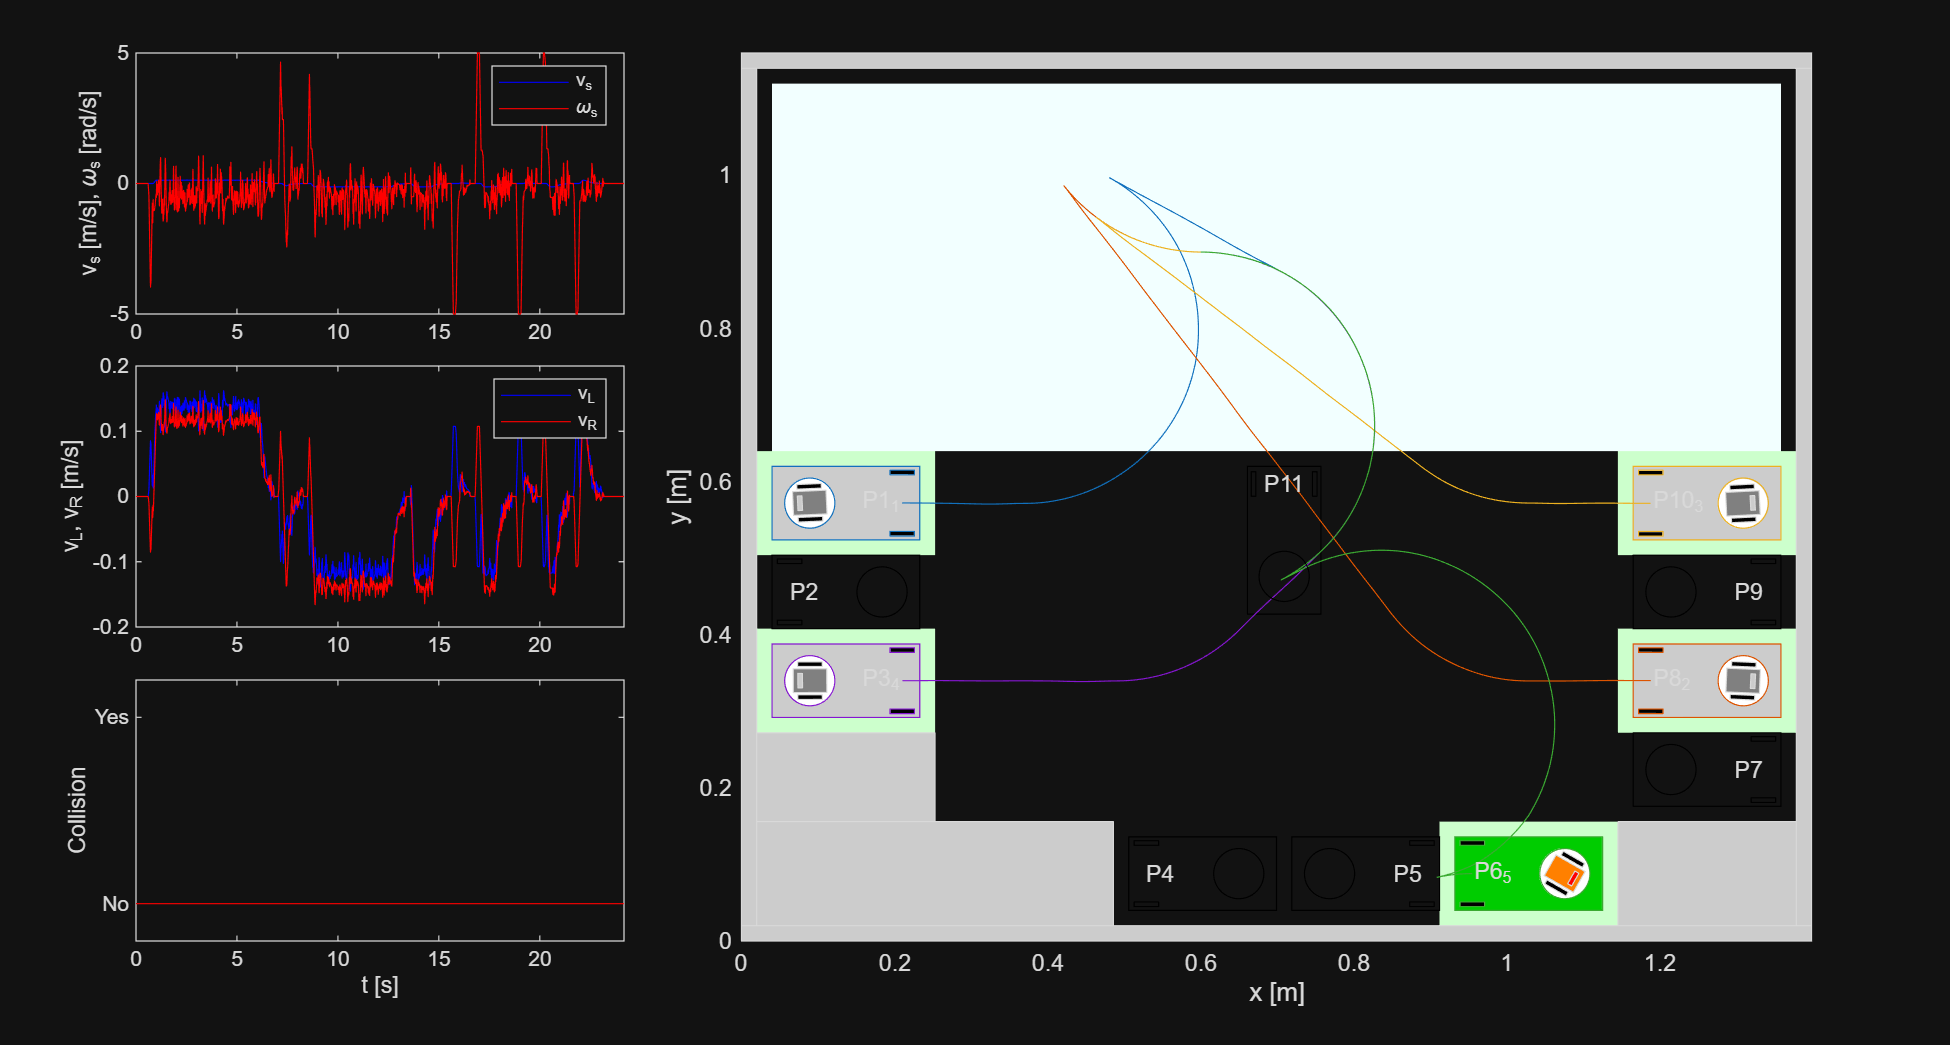


# Summary
 - Robot 1: inside=1, ed=  0.0002 m, ephi=  0.0019 rad, t= 14.8400 s
 - Robot 2: inside=1, ed=  0.0002 m, ephi=  0.0019 rad, t= 14.4200 s
 - Robot 3: inside=1, ed=  0.0005 m, ephi=  0.0006 rad, t= 12.4100 s
 - Robot 4: inside=1, ed=  0.0004 m, ephi=  0.0001 rad, t= 14.7600 s
 - Robot 5: inside=1, ed=  0.0002 m, ephi= -0.0001 rad, t= 24.1700 s


data = simParkingLim(qS, [1, 8, 10, 3, 6], noise, anima);

store('ex3case1', data);
reportCase(data, 5);

    Spot    Error_mm    Error_deg    Time_s    Path_m     WheelEffort_m2_s    Collisions    MeetsTarget
    ____    ________    _________    ______    _______    ________________    __________    ___________

      1     0.21776       0.10969    14.84      1.1298        0.33272             0              1     
      8     0.22826       0.10736    14.42      1.2784        0.39971             0              1     
     10     0.50385      0.034638    12.41     0.99258        0.30858             0              1     
      3     0.35189     0.0047543    14.76       1.146        0.33836             0              1     
      6     0.24281     0.0034749    24.17      1.4487        0.41293             0              1     



### Case 2: From the same known initial configuration S to P2, P9, P7 and P4

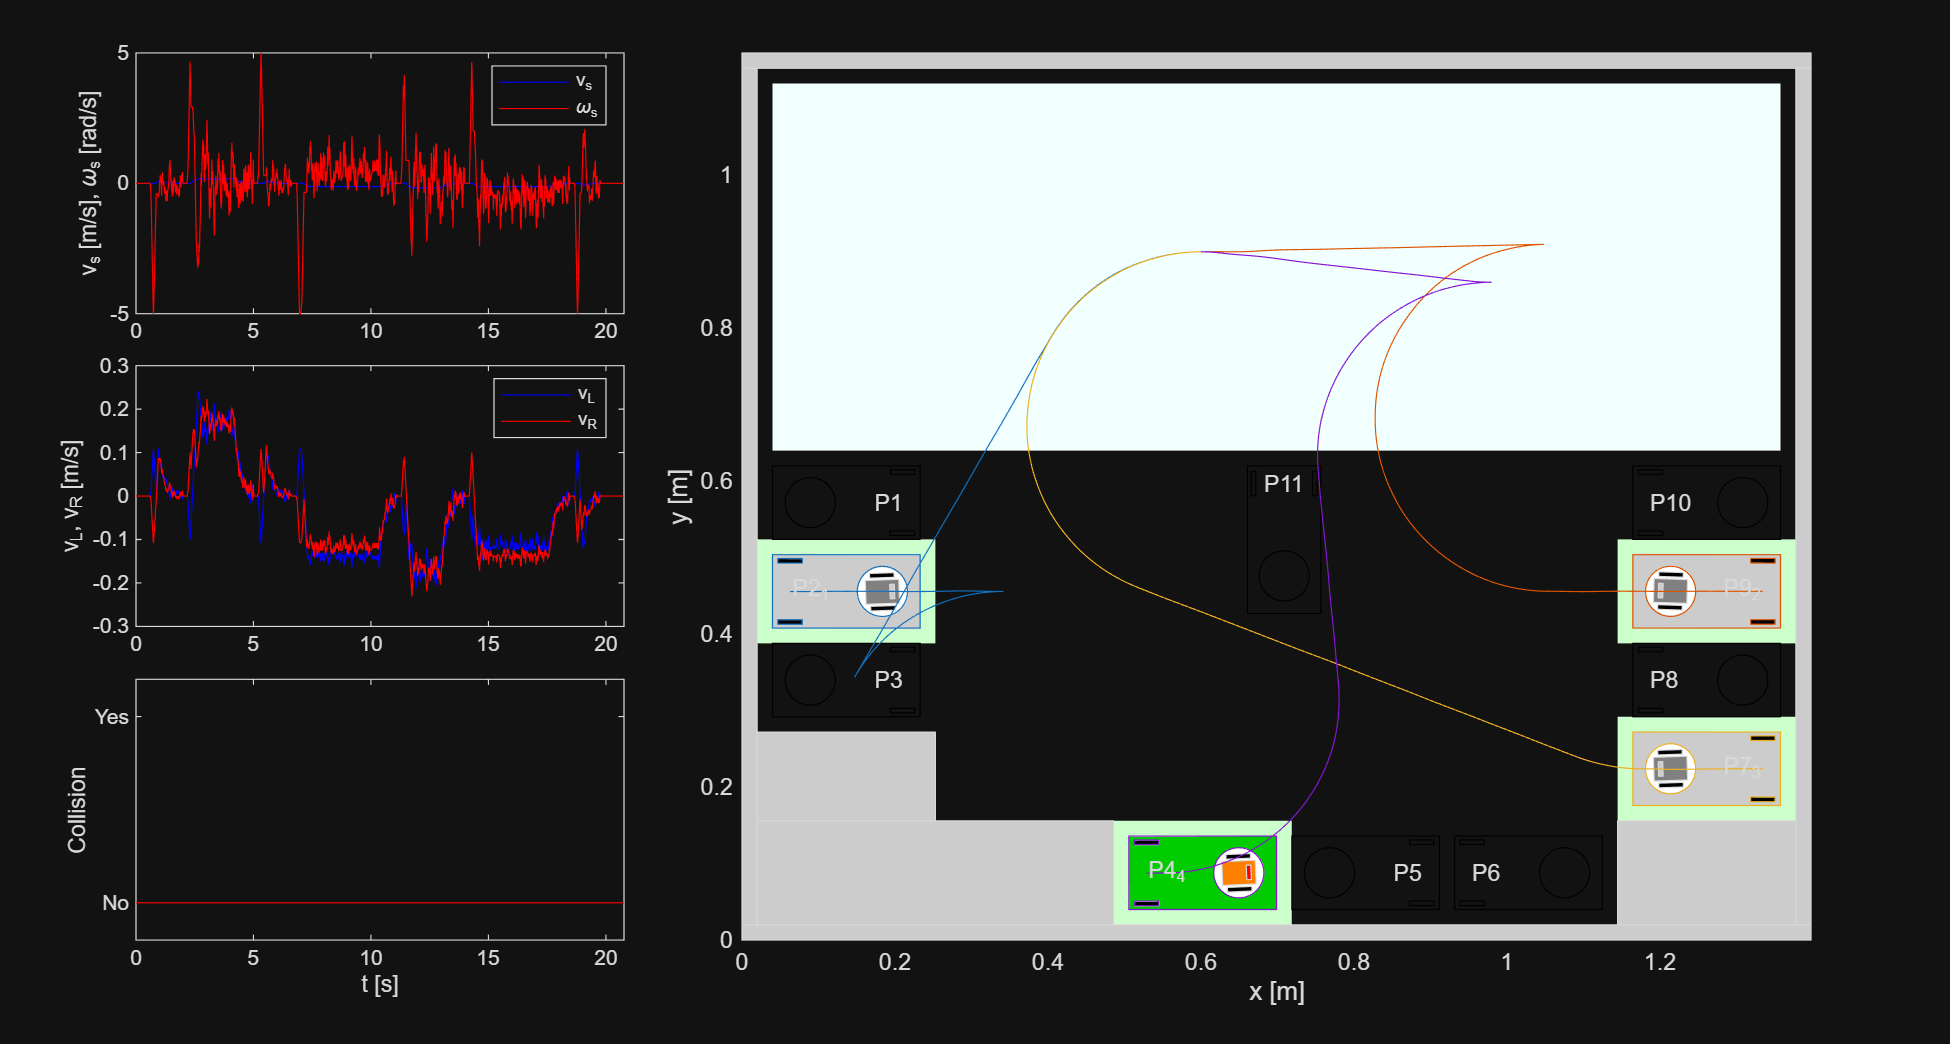


# Summary
 - Robot 1: inside=1, ed=  0.0002 m, ephi=  0.0035 rad, t= 14.7300 s
 - Robot 2: inside=1, ed=  0.0002 m, ephi=  0.0040 rad, t= 16.5900 s
 - Robot 3: inside=1, ed=  0.0001 m, ephi=  0.0019 rad, t= 16.6400 s
 - Robot 4: inside=1, ed=  0.0004 m, ephi= -0.0030 rad, t= 20.7700 s


data = simParkingLim(qS, [2, 9, 7, 4], noise, anima);

store('ex3case2', data);
reportCase(data, 4);

    Spot    Error_mm    Error_deg    Time_s    Path_m    WheelEffort_m2_s    Collisions    MeetsTarget
    ____    ________    _________    ______    ______    ________________    __________    ___________

     2       0.18386     0.19876     14.73     1.2625        0.39141             0              1     
     9       0.15861     0.23061     16.59     1.4354        0.44322             0              1     
     7      0.090287     0.11065     16.64     1.4898        0.45596             0              1     
     4       0.44339     0.17196     20.77     1.4403        0.42793             0              1     



### Case 3: From the same known initial configuration S to P1, P3, P10, P8, P6, P2, P7, P9, P4 and P5

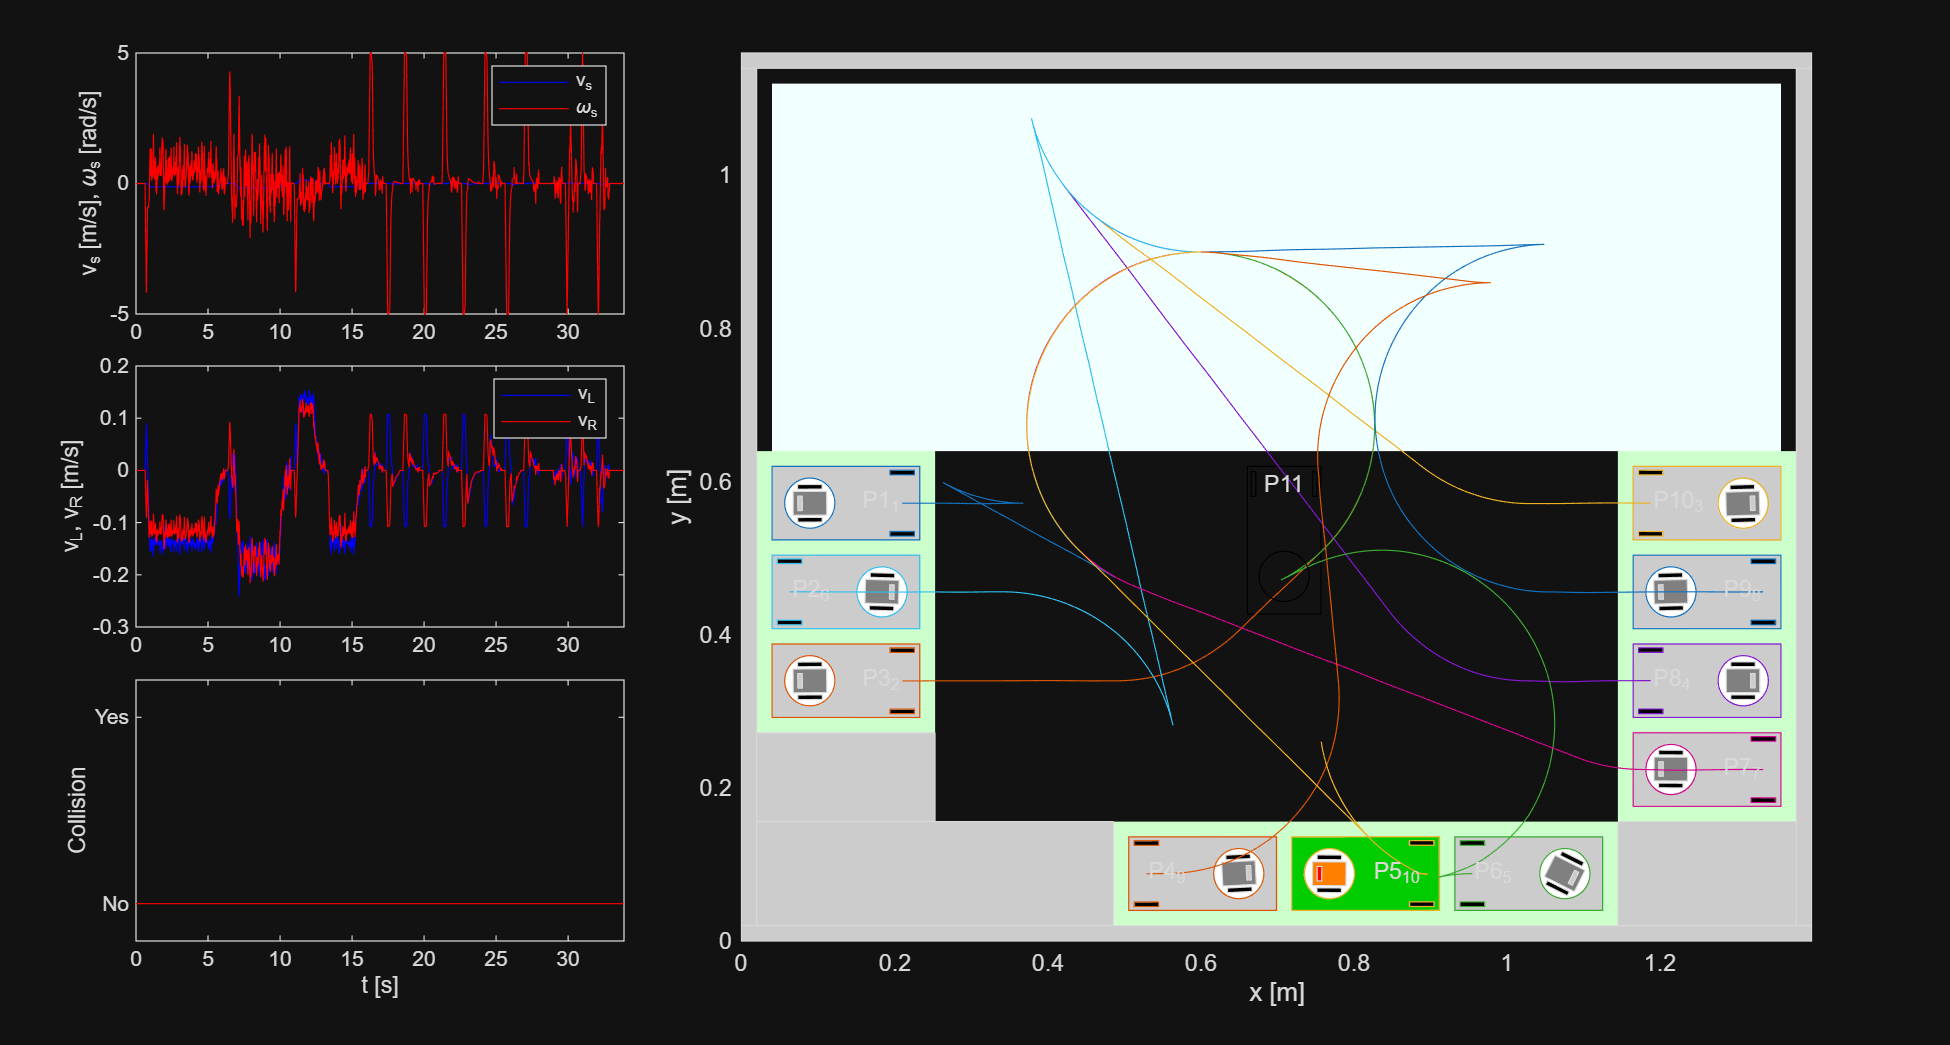


# Summary
 - Robot 1: inside=1, ed=  0.0002 m, ephi= -0.0013 rad, t= 14.3400 s
 - Robot 2: inside=1, ed=  0.0003 m, ephi=  0.0017 rad, t= 14.8000 s
 - Robot 3: inside=1, ed=  0.0006 m, ephi=  0.0041 rad, t= 12.4700 s
 - Robot 4: inside=1, ed=  0.0003 m, ephi=  0.0009 rad, t= 14.4100 s
 - Robot 5: inside=1, ed=  0.0002 m, ephi= -0.0019 rad, t= 24.3900 s
 - Robot 6: inside=1, ed=  0.0002 m, ephi= -0.0003 rad, t= 17.8300 s
 - Robot 7: inside=1, ed=  0.0002 m, ephi=  0.0055 rad, t= 16.5100 s
 - Robot 8: inside=1, ed=  0.0003 m, ephi=  0.0015 rad, t= 16.4800 s
 - Robot 9: inside=1, ed=  0.0003 m, ephi= -0.0055 rad, t= 20.1300 s
 - Robot 10: inside=1, ed=  0.0004 m, ephi= -0.0023 rad, t= 33.8800 s


data = simParkingLim(qS, [1, 3, 10, 8, 6, 2, 7, 9, 4, 5], noise, anima);

store('ex3case3', data);
reportCase(data, 10);

    Spot    Error_mm    Error_deg    Time_s    Path_m     WheelEffort_m2_s    Collisions    MeetsTarget
    ____    ________    _________    ______    _______    ________________    __________    ___________

      1     0.20489     0.071818     14.34      1.1246        0.33099             0              1     
      3     0.34818     0.096505      14.8      1.1458        0.33647             0              1     
     10     0.58125      0.23205     12.47     0.99247         0.3067             0              1     
      8     0.31795     0.052824     14.41      1.2785        0.39954             0              1     
      6     0.23624      0.10971     24.39      1.4466        0.41443             0              1     
      2     0.20387     0.015094     17.83      1.7003        0.53499             0              1     
      7     0.18073      0.31497     16.51      1.4897        0.45664             0              1     
      9     0.29084     0.088719     16.48      1.4362        0

### Case 4: From the same known initial configuration S to P11, P1, P2, P9, P10, P5, P3, P8, P7, P4 and P6

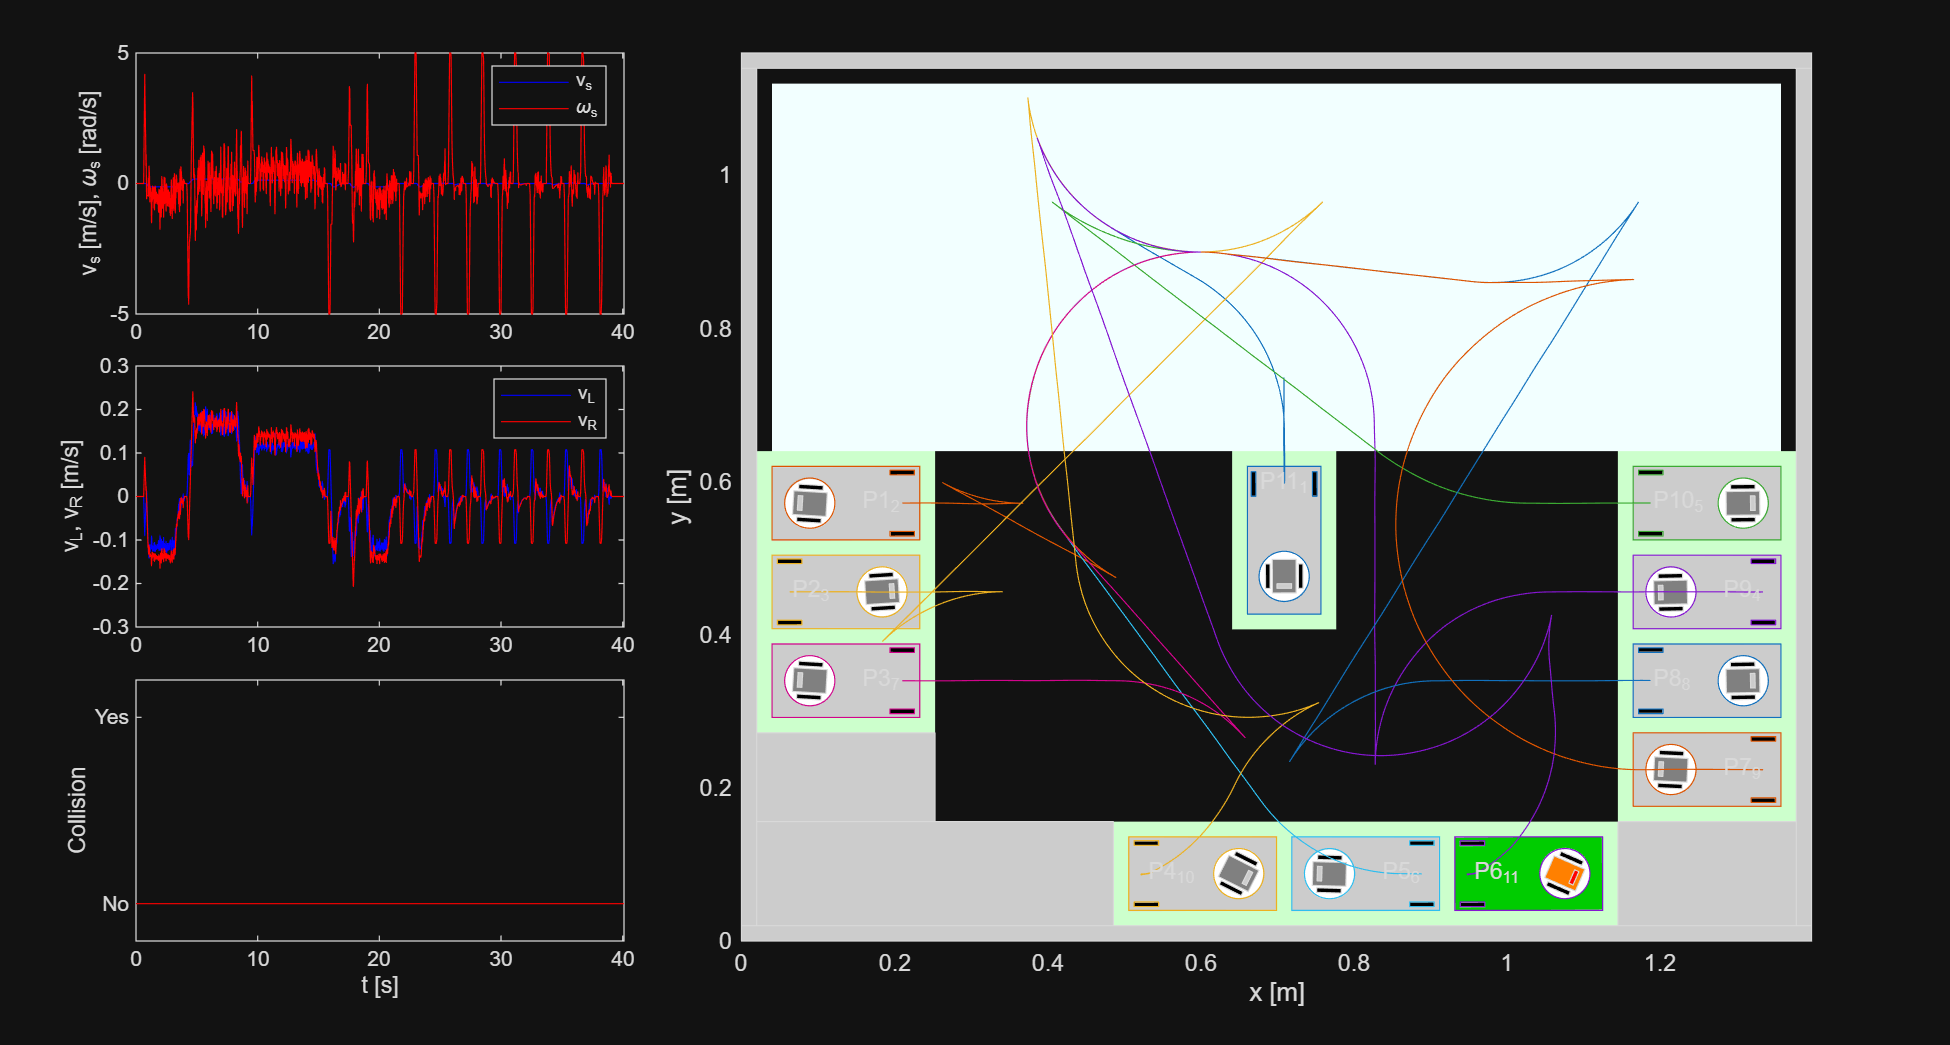


# Summary
 - Robot 1: inside=1, ed=  0.0003 m, ephi= -0.0015 rad, t= 14.9600 s
 - Robot 2: inside=1, ed=  0.0002 m, ephi= -0.0059 rad, t= 14.6500 s
 - Robot 3: inside=1, ed=  0.0002 m, ephi= -0.0025 rad, t= 15.5400 s
 - Robot 4: inside=1, ed=  0.0005 m, ephi= -0.0044 rad, t= 16.3900 s
 - Robot 5: inside=1, ed=  0.0004 m, ephi=  0.0025 rad, t= 13.2600 s
 - Robot 6: inside=1, ed=  0.0003 m, ephi= -0.0020 rad, t= 14.9600 s
 - Robot 7: inside=1, ed=  0.0001 m, ephi=  0.0019 rad, t= 15.7900 s
 - Robot 8: inside=1, ed=  0.0005 m, ephi=  0.0046 rad, t= 22.3500 s
 - Robot 9: inside=1, ed=  0.0004 m, ephi=  0.0025 rad, t= 22.1900 s
 - Robot 10: inside=1, ed=  0.0004 m, ephi= -0.0052 rad, t= 32.5700 s
 - Robot 11: inside=1, ed=  0.0004 m, ephi= -0.0052 rad, t= 40.1100 s


data = simParkingLim(qS, [11, 1, 2, 9, 10, 5, 3, 8, 7, 4, 6], noise, anima);

store('ex3case4', data);
reportCase(data, 11);

    Spot    Error_mm    Error_deg    Time_s    Path_m     WheelEffort_m2_s    Collisions    MeetsTarget
    ____    ________    _________    ______    _______    ________________    __________    ___________

     11      0.31495    0.085951     14.96     0.83903        0.23495             0              1     
      1      0.21531     0.33972     14.65      1.1271        0.33393             0              1     
      2      0.15985     0.14199     15.54       1.444        0.46124             0              1     
      9      0.45158     0.25279     16.39      1.4356        0.43701             0              1     
     10      0.38118     0.14501     13.26      1.1151        0.33183             0              1     
      5      0.27557     0.11461     14.96      1.1834        0.35159             0              1     
      3     0.074636     0.11147     15.79      1.3365        0.40122             0              1     
      8      0.54951     0.26437     22.35       1.982        0

### Case 5: From random initial configurations to random parking spots

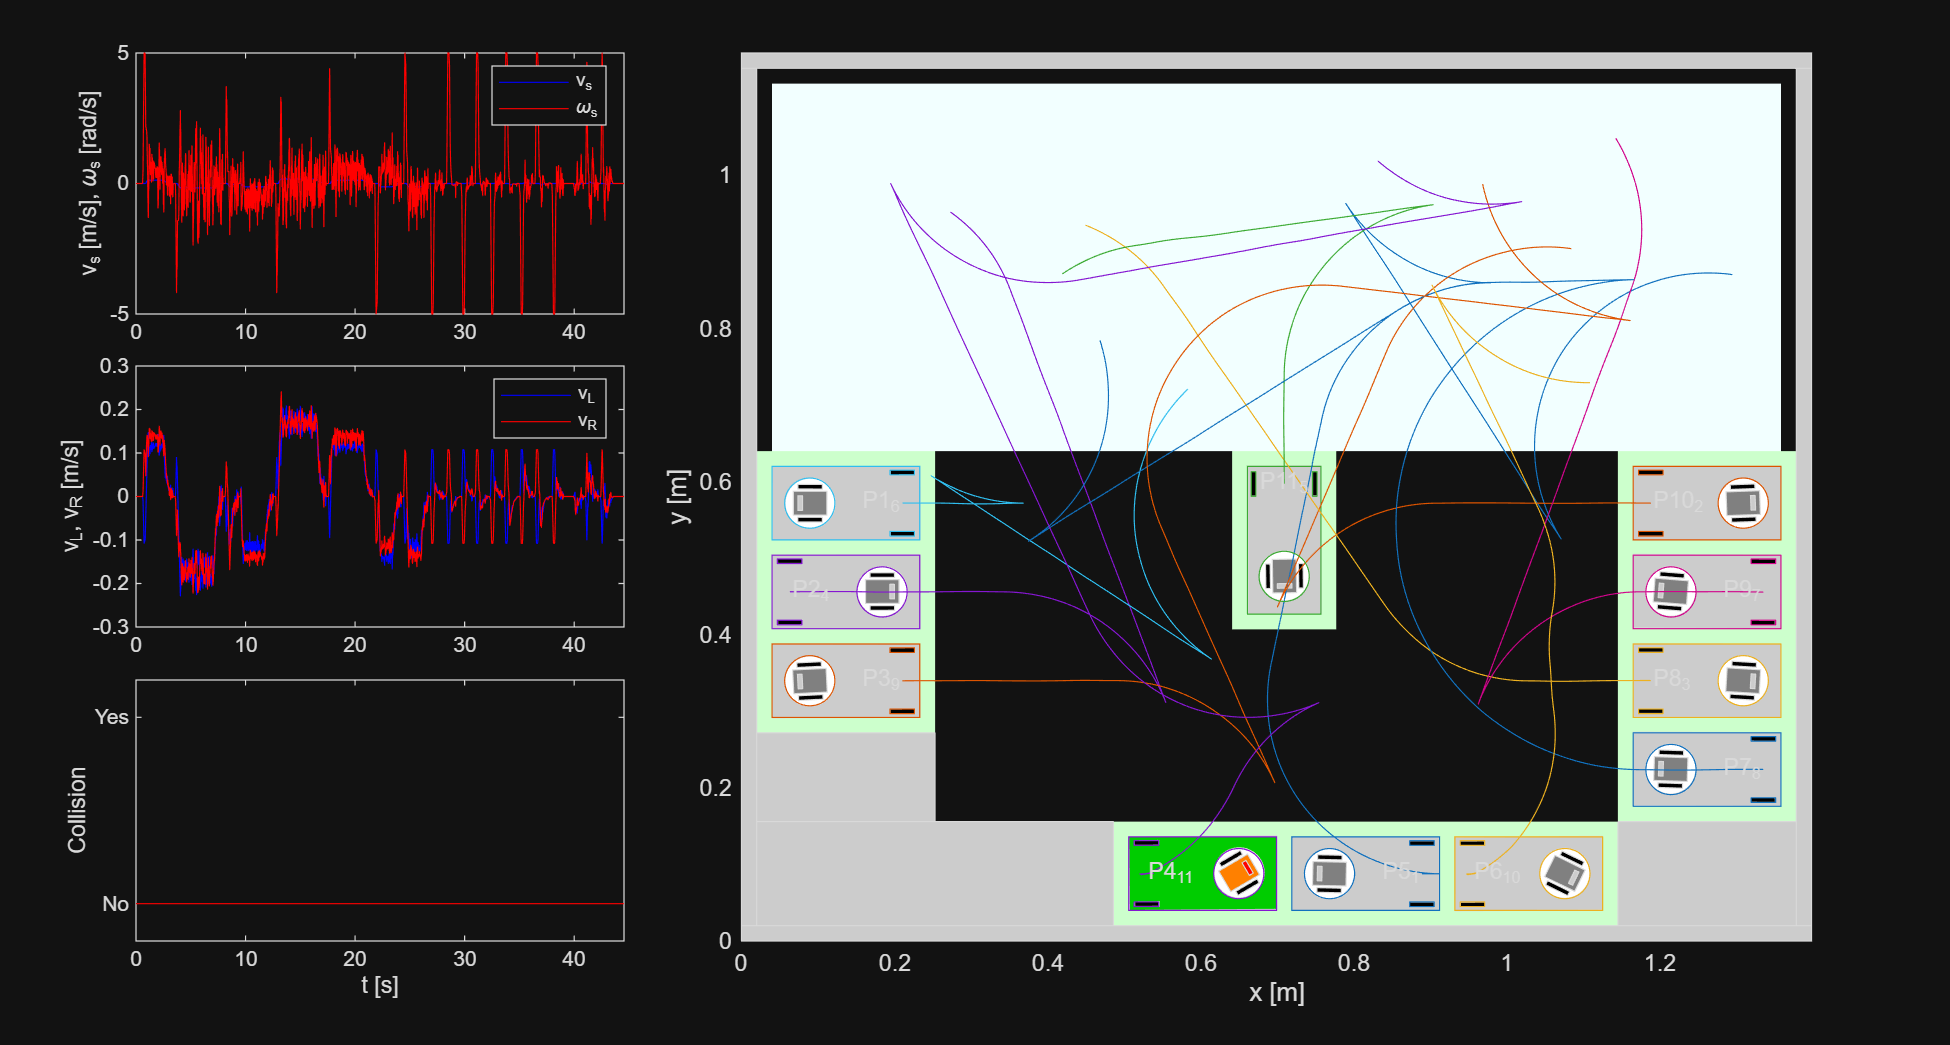


# Summary
 - Robot 1: inside=1, ed=  0.0002 m, ephi=  0.0003 rad, t= 27.2900 s
 - Robot 2: inside=1, ed=  0.0001 m, ephi=  0.0009 rad, t= 14.6800 s
 - Robot 3: inside=1, ed=  0.0003 m, ephi=  0.0017 rad, t= 12.8600 s
 - Robot 4: inside=1, ed=  0.0004 m, ephi= -0.0025 rad, t= 14.5600 s
 - Robot 5: inside=1, ed=  0.0005 m, ephi= -0.0024 rad, t= 12.6200 s
 - Robot 6: inside=1, ed=  0.0005 m, ephi= -0.0009 rad, t= 14.1100 s
 - Robot 7: inside=1, ed=  0.0003 m, ephi=  0.0079 rad, t= 14.4700 s
 - Robot 8: inside=1, ed=  0.0003 m, ephi=  0.0033 rad, t= 27.1200 s
 - Robot 9: inside=1, ed=  0.0002 m, ephi= -0.0028 rad, t= 23.7700 s
 - Robot 10: inside=1, ed=  0.0004 m, ephi= -0.0061 rad, t= 33.6800 s
 - Robot 11: inside=1, ed=  0.0005 m, ephi= -0.0068 rad, t= 44.5500 s


data = simParkingLim([], [0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0], noise, anima);

store('ex3case5', data);
reportCase(data, 11);

    Spot    Error_mm    Error_deg    Time_s    Path_m     WheelEffort_m2_s    Collisions    MeetsTarget
    ____    ________    _________    ______    _______    ________________    __________    ___________

      5     0.22775     0.018773     27.29      2.3228         0.6992             0              1     
     10     0.07551     0.050815     14.68       1.204        0.36447             0              1     
      8     0.28102       0.1001     12.86      1.0188        0.31254             0              1     
      2     0.38394      0.14342     14.56      1.2603        0.39317             0              1     
     11     0.50417      0.13869     12.62     0.96148         0.2908             0              1     
      1     0.45913     0.054264     14.11      1.1347        0.34508             0              1     
      9      0.2644      0.45202     14.47      1.2182        0.37442             0              1     
      7     0.30076      0.18877     27.12      2.3434        0

## Prepare ZIP for submission

After running all sections, save this Live Script with its output. Then run prepare from the MATLAB Command Window in this folder to package the saved report, the source files and the generated MAT files.

The wheel-speed effort is the time integral of vL squared plus vR squared. Collisions count the starts of contact events. The last column checks the 1 mm and 0.5 degree tolerances together with the parking-area flag. The simulator returns data for completed robots. A warning shows how many are missing.

## Result summary helper

function reportCase(data, expected)
    if numel(data) < expected
        warning('%d of %d robots completed the case.', numel(data), expected);
    end
    values = zeros(numel(data), 8);
    for i = 1:numel(data)
        d = data(i);
        poseError = d.goalPose - d.qEnd(1:3);
        positionMm = 1000*norm(poseError(1:2));
        headingDeg = abs(rad2deg(wrapToPi(poseError(3))));
        lengthM = sum(hypot(diff(d.x), diff(d.y)));
        effort = trapz(d.t, d.vl.^2 + d.vr.^2);
        collisions = nnz(diff([false, logical(d.c(:).')]) == 1);
        values(i,:) = [d.goalId, positionMm, headingDeg, d.tEnd, lengthM, effort, collisions, ...
            d.inside && positionMm <= 1 && headingDeg <= 0.5];
    end
    disp(array2table(values, 'VariableNames', {'Spot', 'Error_mm', 'Error_deg', ...
        'Time_s', 'Path_m', 'WheelEffort_m2_s', 'Collisions', 'MeetsTarget'}));
end